    ti_f= 6.65;
    ti_s= 6.65;
    isen="C:\Users\fabia\Desktop\DPB4\Datos Reales\1. Primer voluntario (Alfonso)\Toma 5\VOLUNTARIO_1.csv";
    sagital="C:\Users\fabia\Desktop\DPB4\Datos Reales\1. Primer voluntario (Alfonso)\Toma 5\sagital2.xlsx";
    fronto="C:\Users\fabia\Desktop\DPB4\Datos Reales\1. Primer voluntario (Alfonso)\Toma 5\frontal (4).xlsm";
    inclinacion=2.5;

**##Leyendas:**

**Frontal:**

1.cod_fnt (Frontal) --> codo

2.cod_med_fnt (Frontal) --> codo medial

3.eld_fnt (Frontal) --> estático left down

4.erd_fnt (Frontal) --> estático right down

5.esc_fnt (Frontal) --> escápula

6.est_fnt (Frontal) --> esternón

7.etl_fnt (Frontal) --> estático left 

8.etr_fnt (Frontal) --> estático right

9.h_ant_fnt (Frontal) --> hombro anterior

10.h_post_fnt (Frontal) --> hombro posterior

11.hnd_fnt (Frontal) --> hand

12.rad_fnt (Frontal) --> radio

13.rdn_fnt (Frontal) --> reference down frontal

14.rhz_fnt (Frontal) --> reference horz

15.rup_fnt (Frontal) --> reference up

**Sagital:**

1.cod_sag (Sagital) --> codo

2.cub_sag (Sagital) --> cubito

3.rad_sag (Sagital) --> radio

4.mnk_sag (Sagital) --> muñeca

5.h_post_sag (Sagital) --> hombro posterior

6.h_ant_sag (Sagital) --> hombro anterior

7.est_sag (Sagital) --> esternon

8.esc_sag (Sagital) --> escápula

    % Leer y procesar archivo sagital
    filename = sagital;
    dataStructSagital = readAndProcessExcel(filename);
    
    % Leer y procesar archivo frontal
    filename = fronto;
    dataStructFrontal = readAndProcessExcel(filename);
    
    % Determinar el número máximo de filas
    allFieldNames = union(fieldnames(dataStructSagital), fieldnames(dataStructFrontal));
    maxRows = 0;
    
    % Calcular el número máximo de filas en ambas estructuras
    for i = 1:numel(allFieldNames)
        if isfield(dataStructSagital, allFieldNames{i})
            maxRows = max(maxRows, size(dataStructSagital.(allFieldNames{i}), 1));
        end
        if isfield(dataStructFrontal, allFieldNames{i})
            maxRows = max(maxRows, size(dataStructFrontal.(allFieldNames{i}), 1));
        end
    end
    
    % Ajustar cada campo en ambas estructuras
    disp("Campos ajustados para Sagital:");

Campos ajustados para Sagital:


    dataStructSagital = adjustFieldsToMaxRows(dataStructSagital, maxRows);
    
    disp("Campos ajustados para Frontal:");

Campos ajustados para Frontal:


    dataStructFrontal = adjustFieldsToMaxRows(dataStructFrontal, maxRows);
    
    % Crear matrices con nombres iguales a los índices obtenidos
    % Combinar campos de sagital y frontal para asegurarse de cubrir todos
    allFieldNames = union(fieldnames(dataStructSagital), fieldnames(dataStructFrontal));
    
    for i = 1:numel(allFieldNames)
        fieldName = allFieldNames{i};
        if isfield(dataStructSagital, fieldName)
            assignin('base', fieldName, dataStructSagital.(fieldName));
            fprintf("Matriz creada en base workspace: %s (Sagital)\n", fieldName);
        end
        if isfield(dataStructFrontal, fieldName)
            assignin('base', fieldName, dataStructFrontal.(fieldName));
            fprintf("Matriz creada en base workspace: %s (Frontal)\n", fieldName);
        end
    end

Matriz creada en base workspace: cod_fnt (Frontal)
Matriz creada en base workspace: cod_med_fnt (Frontal)


Matriz creada en base workspace: cod_sag (Sagital)
Matriz creada en base workspace: cub_sag (Sagital)


Matriz creada en base workspace: eld_fnt (Frontal)
Matriz creada en base workspace: erd_fnt (Frontal)
Matriz creada en base workspace: esc_fnt (Frontal)


Matriz creada en base workspace: esc_sag (Sagital)


Matriz creada en base workspace: est_fnt (Frontal)


Matriz creada en base workspace: est_sag (Sagital)


Matriz creada en base workspace: etl_fnt (Frontal)
Matriz creada en base workspace: etr_fnt (Frontal)
Matriz creada en base workspace: h_ant_fnt (Frontal)


Matriz creada en base workspace: h_ant_sag (Sagital)


Matriz creada en base workspace: h_post_fnt (Frontal)


Matriz creada en base workspace: h_post_sag (Sagital)


Matriz creada en base workspace: hnd_fnt (Frontal)


Matriz creada en base workspace: mnk_sag (Sagital)


Matriz creada en base workspace: rad_fnt (Frontal)


Matriz creada en base workspace: rad_sag (Sagital)


Matriz creada en base workspace: rdn_fnt (Frontal)
Matriz creada en base workspace: rhz_fnt (Frontal)
Matriz creada en base workspace: rup_fnt (Frontal)


    
    % Función para leer y procesar el archivo Excel
    function dataStruct = readAndProcessExcel(filename)
        % Leer todo el archivo Excel en una celda para mayor flexibilidad
        data = readcell(filename);
        
        % Inicializar la estructura de datos
        dataStruct = struct();
        currentSection = '';  % Nombre de la sección actual
        
        % Recorrer cada fila del archivo leído
        for i = 1:size(data, 1)
            line = data(i, :); % Leer la fila actual como celda
            
            % Ignorar filas vacías
            if all(cellfun(@isempty, line))
                continue;
            end
            
            % Detectar inicio de una nueva sección
            if ischar(line{1}) && ~isempty(line{1}) && ~contains(line{1}, {'Key images', 'Distances', 'Time', 'Name'})
                currentSection = matlab.lang.makeValidName(line{1}); % Convertir el índice en un nombre válido
                dataStruct.(currentSection) = []; % Crear una nueva entrada en la estructura
            elseif ~isempty(currentSection) && isnumeric(line{1})
                % Procesar los datos numéricos dentro de la sección actual
                numericData = cell2mat(line(~cellfun(@isempty, line)));
                dataStruct.(currentSection) = [dataStruct.(currentSection); numericData];
            end
        end
        
        % Eliminar campos vacíos de la estructura
        fieldsToRemove = fieldnames(dataStruct);
        for i = 1:length(fieldsToRemove)
            if isempty(dataStruct.(fieldsToRemove{i}))
                dataStruct = rmfield(dataStruct, fieldsToRemove{i});
            end
        end
    end
    
    % Función para ajustar campos al máximo número de filas
    function dataStruct = adjustFieldsToMaxRows(dataStruct, maxRows)
        fieldNames = fieldnames(dataStruct);
        
        for i = 1:numel(fieldNames)
            fieldName = fieldNames{i};
            data = dataStruct.(fieldName);
            
            if size(data, 1) < maxRows
                % Calcular la diferencia en la columna de tiempo (Time (ms))
                timeColumn = data(:, 1);
                timeDiff = timeColumn(2) - timeColumn(1);
                
                % Extender los valores **hacia adelante** (agregando en la última fila)
                while size(data, 1) < maxRows
                    newTime = data(end, 1) + timeDiff; % Nuevo tiempo es el último más la diferencia
                    newRow = [newTime, data(end, 2:end)]; % Copiar valores excepto tiempo
                    data = [data; newRow]; % Agregar al final de la matriz
                end
                
                % Actualizar el campo ajustado
                dataStruct.(fieldName) = data;
            end
        end
    end

    % Verificar si existen las referencias necesarias
    if all(isfield(dataStructFrontal, {'rup_fnt', 'rdn_fnt', 'rhz_fnt'})) && ...
       all(isfield(dataStructFrontal, {'etl_fnt', 'etr_fnt', 'eld_fnt', 'erd_fnt'}))
       
        % Obtener las referencias móviles   
        refUp = dataStructFrontal.rup_fnt; % [Time, X, Y]
        refDown = dataStructFrontal.rdn_fnt; % [Time, X, Y]
        refHorz = dataStructFrontal.rhz_fnt; % [Time, X]
        
        % Obtener las referencias estáticas
        estIzq = dataStructFrontal.etl_fnt; % [Time, X, Y]
        estDer = dataStructFrontal.etr_fnt; % [Time, X, Y]
        estIzqBajo = dataStructFrontal.eld_fnt; % [Time, X, Y]
        estDerBajo = dataStructFrontal.erd_fnt; % [Time, X, Y]
        
        % ========================
        % Calcular factores de crecimiento (moviles)
        % ========================
        % Normalización en el eje Y usando referencias móviles
        Y_ref_initial = refUp(1, 3) - refDown(1, 3);
        Y_actual = refUp(:, 3) - refDown(:, 3);
        factor_Y_growth = Y_ref_initial ./ Y_actual;
        factor_Y_growth(~isfinite(factor_Y_growth)) = 1; % Manejar NaN o Inf
        
        % Normalización en el eje X usando referencias móviles
        X_ref_initial = refUp(1, 2) - refHorz(1, 2);
        X_actual = refUp(:, 2) - refHorz(:, 2);
        factor_X_growth = X_ref_initial ./ X_actual;
        factor_X_growth(~isfinite(factor_X_growth)) = 1; % Manejar NaN o Inf
        
        % ========================
        % Ajustar traslación (estáticas)
        % ========================
        % Traslación en el eje Y
        Y_translation = estIzq(1, 3) - (refUp(:, 3) .* factor_Y_growth);
        
        % Traslación en el eje X
        X_translation = estIzq(1, 2) - (refUp(:, 2) .* factor_X_growth);
        
        % ========================
        % Crear nuevas matrices normalizadas (_normXY)
        % ========================
        fieldNamesFrontal = fieldnames(dataStructFrontal);
        for i = 1:numel(fieldNamesFrontal)
            fieldName = fieldNamesFrontal{i};
            data = dataStructFrontal.(fieldName);
            
            % Verificar que la matriz tenga al menos 3 columnas (Time, X, Y)
            if size(data, 2) >= 3
                % Crear una nueva matriz normalizada en X e Y
                data_normXY = data; % Copia los datos originales
                data_normXY(:, 2) = (data(:, 2) .* factor_X_growth) + X_translation; % Normalizar y trasladar X
                data_normXY(:, 3) = (data(:, 3) .* factor_Y_growth) + Y_translation; % Normalizar y trasladar Y
                
                % Guardar la nueva matriz con el sufijo _normXY
                newFieldName = [fieldName, '_normXY'];
                dataStructFrontal.(newFieldName) = data_normXY;
                
                % Asignar al workspace para inspección
                assignin('base', newFieldName, data_normXY);
                
                fprintf("Matriz creada en base workspace: %s\n", newFieldName);
            end
        end
        
        % ========================
        % Validación de normalización
        % ========================
        refUpNormalized = dataStructFrontal.rup_fnt_normXY;
        refDownNormalized = dataStructFrontal.rdn_fnt_normXY;
        refHorzNormalized = dataStructFrontal.rhz_fnt_normXY;
    
        % Recalcular diferencias normalizadas en Y
        Y_normalized = refUpNormalized(:, 3) - refDownNormalized(:, 3);
        % Recalcular diferencias normalizadas en X
        X_normalized = refUpNormalized(:, 2) - refHorzNormalized(:, 2);
        
        % Crear matrices "reference_final_Y" y "reference_final_X"
        reference_final_Y = [refUpNormalized(:, 1), Y_normalized]; % [Time, Normalized Y diff]
        reference_final_X = [refUpNormalized(:, 1), X_normalized]; % [Time, Normalized X diff]
        
        % Verificar que las diferencias sean constantes
        if all(abs(Y_normalized - Y_ref_initial) < 1e-6)
            fprintf("✅ La normalización en Y se realizó correctamente. Todas las diferencias en Y son constantes.\n");
        else
            fprintf("⚠️ Error en la normalización en Y. Las diferencias no son constantes.\n");
        end
        
        if all(abs(X_normalized - X_ref_initial) < 1e-6)
            fprintf("✅ La normalización en X se realizó correctamente. Todas las diferencias en X son constantes.\n");
        else
            fprintf("⚠️ Error en la normalización en X. Las diferencias no son constantes.\n");
        end
    end

Matriz creada en base workspace: est_fnt_normXY
Matriz creada en base workspace: h_ant_fnt_normXY
Matriz creada en base workspace: h_post_fnt_normXY
Matriz creada en base workspace: cod_fnt_normXY
Matriz creada en base workspace: cod_med_fnt_normXY
Matriz creada en base workspace: rad_fnt_normXY
Matriz creada en base workspace: hnd_fnt_normXY
Matriz creada en base workspace: eld_fnt_normXY
Matriz creada en base workspace: erd_fnt_normXY
Matriz creada en base workspace: etr_fnt_normXY
Matriz creada en base workspace: etl_fnt_normXY
Matriz creada en base workspace: rup_fnt_normXY
Matriz creada en base workspace: rdn_fnt_normXY
Matriz creada en base workspace: rhz_fnt_normXY
Matriz creada en base workspace: esc_fnt_normXY


✅ La normalización en Y se realizó correctamente. Todas las diferencias en Y son constantes.


✅ La normalización en X se realizó correctamente. Todas las diferencias en X son constantes.


    % Verificación y visualización de las diferencias en Y
    if isfield(dataStructFrontal, 'reference_up_normXY') && isfield(dataStructFrontal, 'reference_down_normXY')
        % Obtener las matrices normalizadas
        refUpNormalized = dataStructFrontal.reference_up_normXY;
        refDownNormalized = dataStructFrontal.reference_down_normXY;
        
        % Calcular la diferencia en Y para cada fotograma
        Y_difference = refUpNormalized(:, 3) - refDownNormalized(:, 3);
        
        % Imprimir los valores en formato de tabla
        fprintf('%10s %15s %15s %15s\n', 'Time (ms)', 'Y (Up)', 'Y (Down)', 'Difference');
        fprintf('%10s %15s %15s %15s\n', '----------', '--------------', '--------------', '--------------');
        for i = 1:size(refUpNormalized, 1)
            fprintf('%10.3f %15.3f %15.3f %15.3f\n', ...
                refUpNormalized(i, 1), refUpNormalized(i, 3), refDownNormalized(i, 3), Y_difference(i));
        end
        
        % Verificar si las diferencias están dentro del margen permitido
        Y_ref_initial = Y_difference(1); % Usar la primera diferencia como referencia
        max_error = 0.001; % Margen de error permitido
        consistent = all(abs(Y_difference - Y_ref_initial) <= max_error);
        
        % Mostrar resultados de la verificación
        if consistent
            fprintf("\n La normalización en Y es consistente. Todas las diferencias están dentro del margen de %.3f.\n", max_error);
        else
            fprintf("\n La normalización en Y no es consistente. Algunas diferencias superan el margen de %.3f.\n", max_error);
            % Mostrar fotogramas con errores
            indices_inconsistentes = find(abs(Y_difference - Y_ref_initial) > max_error);
            disp("Fotogramas inconsistentes:");
            disp(indices_inconsistentes);
            disp("Diferencias correspondientes:");
            disp(Y_difference(indices_inconsistentes));
        end
    else
        fprintf("No se encontraron las matrices normalizadas 'reference_up_normY' y 'reference_down_normY' para la verificación.\n");
    end

No se encontraron las matrices normalizadas 'reference_up_normY' y 'reference_down_normY' para la verificación.


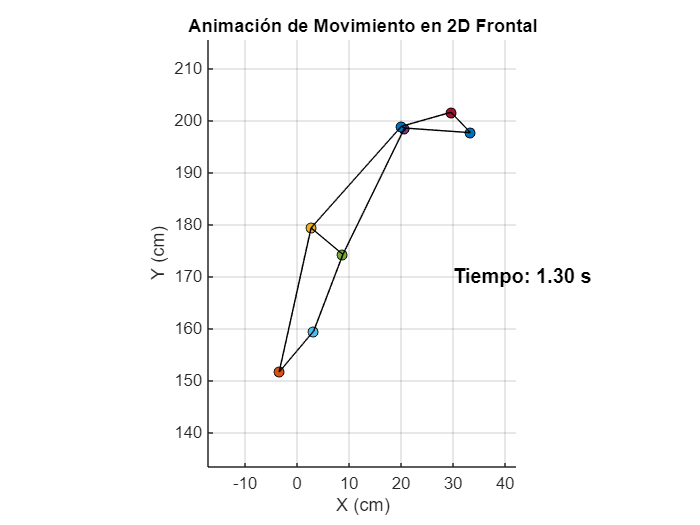

    % Lista de matrices a incluir en la animación
    matrices_a_animar = {'est_fnt_normXY', 'hnd_fnt_normXY', 'cod_fnt_normXY', 'h_ant_fnt_normXY', ...
                         'cod_med_fnt_normXY', 'rad_fnt_normXY', 'esc_fnt_normXY', 'h_post_fnt_normXY'};
    % Aplicar Filtro Pasa-Baja Butterworth a todas las matrices
    fs = 29.97; % Frecuencia de muestreo estimada (ajustar si es necesario)
    fc = 6;   % Frecuencia de corte en Hz
    orden = 4; % Orden del filtro
    [b, a] = butter(orden, fc/(fs/2), 'low'); 
    
    for i = 1:length(matrices_a_animar)
        matriz_nombre = matrices_a_animar{i}; % Obtener el nombre de la matriz
        if isfield(dataStructSagital, matriz_nombre)
            matriz_original = dataStructSagital.(matriz_nombre);
            
            % Aplicar el filtro Butterworth en los ejes X e Y
            matriz_filtrada = matriz_original;
            matriz_filtrada(:, 2) = filtfilt(b, a, matriz_original(:, 2)); % Filtro en X
            matriz_filtrada(:, 3) = filtfilt(b, a, matriz_original(:, 3)); % Filtro en Y
            
            % Guardar la matriz filtrada con el mismo nombre
            dataStructSagital.(matriz_nombre) = matriz_filtrada;
        end
    end
    % Definir colores para cada punto
    colores = lines(length(matrices_a_animar));
    
    % Obtener el número de fotogramas de la animación
    num_frames = size(eval(matrices_a_animar{1}), 1); % Todas tienen el mismo número de filas
    
    % Crear figura
    figure;
    hold on;
    xlabel('X (cm)');
    ylabel('Y (cm)');
    title('Animación de Movimiento en 2D Frontal');
    grid on;
    axis equal;
    xlim([-17.0 42.1])
    ylim([133.3 215.6])
    
    % Obtener los datos de cada punto en el primer frame
    puntos = gobjects(size(matrices_a_animar));
    lineas = gobjects(9, 1); % Hay 9 conexiones definidas
    
    for i = 1:length(matrices_a_animar)
        matriz = eval(matrices_a_animar{i});
        puntos(i) = plot(matriz(1, 2), matriz(1, 3), 'o', ...
                         'MarkerFaceColor', colores(i, :), ...
                         'MarkerEdgeColor', 'k', ...
                         'DisplayName', matrices_a_animar{i});
    end
    
    % Definir las conexiones (pares de índices de puntos)
    conexiones = [
        1, 7; % Esternon con escapula
        7, 8; % Escapula con hombro posterior
        1, 4; % Esternon con hombro anterior
        8, 4; % Hombro posterior con hombro anterior
        5, 4; % Codo medial con hombro anterior
        3, 8; % Codo con hombro posterior
        5, 3; % Codo medial con codo
        6, 5; % Radio con codo medial
        2, 3; % Mano con codo
        6, 2; % Radio con mano
    ];
    
    % Crear líneas iniciales
    for i = 1:size(conexiones, 1)
        idx1 = conexiones(i, 1);
        idx2 = conexiones(i, 2);
        matriz1 = eval(matrices_a_animar{idx1});
        matriz2 = eval(matrices_a_animar{idx2});
        lineas(i) = plot([matriz1(1, 2), matriz2(1, 2)], ...
                         [matriz1(1, 3), matriz2(1, 3)], ...
                         '-', 'Color', 'k');
    end
    % Calcular la frecuencia de muestreo
    frame_rate = 1 / 0.033367; % Frecuencia en Hz
    tiempo_texto = text(30, 170.0, sprintf('Tiempo: %.2f s', 0), ...
                        'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
    
    % Animación
    for k = 1:num_frames
        for i = 1:length(matrices_a_animar)
            matriz = eval(matrices_a_animar{i});
            set(puntos(i), 'XData', matriz(k, 2), 'YData', matriz(k, 3)); % Actualizar posición
        end
    
        % Actualizar líneas
        for i = 1:size(conexiones, 1)
            idx1 = conexiones(i, 1);
            idx2 = conexiones(i, 2);
            matriz1 = eval(matrices_a_animar{idx1});
            matriz2 = eval(matrices_a_animar{idx2});
            set(lineas(i), 'XData', [matriz1(k, 2), matriz2(k, 2)], ...
                           'YData', [matriz1(k, 3), matriz2(k, 3)]);
        end
        % Calcular el tiempo exacto en segundos
        tiempo_actual = k / frame_rate;
    
        % Actualizar el texto con el tiempo actual
        set(tiempo_texto, 'String', sprintf('Tiempo: %.2f s', tiempo_actual));
        pause(4*0.033367); % Pausa entre fotogramas para controlar la velocidad
    end
    
    hold off;

    % Listado de matrices a procesar
    matrices_a_procesar = {'mnk_sag', 'cod_sag', 'h_ant_sag', 'rad_sag', 'cub_sag', 'h_post_sag', 'esc_sag', 'est_sag'};
    escapula_data = dataStructSagital.esc_sag;
    
    % Conversión de 3.8° a radianes
    angulo_inclinacion_rad = deg2rad(inclinacion);
    
    % Obtener el desplazamiento inicial en X para la escápula
    escapula_referencia_X = escapula_data(:, 2); % Valores originales del eje X de la escápula
    escapula_referencia_X_inicial = escapula_referencia_X(1); % Tomar el primer valor como referencia
    
    % Calcular el ajuste en Y para todos los puntos
    ajuste_Y = sin(angulo_inclinacion_rad) * (escapula_referencia_X - escapula_referencia_X_inicial);
    
    % Corregir y guardar las nuevas matrices
    for i = 1:length(matrices_a_procesar)
        matriz_nombre = matrices_a_procesar{i};
        if isfield(dataStructSagital, matriz_nombre)
            matriz_original = dataStructSagital.(matriz_nombre);
            
            % Ajustar el eje X para que la escápula permanezca constante
            desplazamiento_X = escapula_referencia_X - escapula_referencia_X_inicial;
            matriz_ajustada = matriz_original;
            matriz_ajustada(:, 2) = matriz_original(:, 2) - desplazamiento_X; % Ajustar X
            
            % Ajustar el eje Y usando trigonometría
            matriz_ajustada(:, 3) = matriz_original(:, 3) - ajuste_Y; % Ajustar Y
            
            % Guardar la nueva matriz con el sufijo _fixed
            nuevo_nombre = [matriz_nombre, '_fixed'];
            dataStructSagital.(nuevo_nombre) = matriz_ajustada;
            
            % Asignar al workspace para inspección
            assignin('base', nuevo_nombre, matriz_ajustada);
            fprintf("Matriz creada: %s\n", nuevo_nombre);
        end
    end

Matriz creada: mnk_sag_fixed
Matriz creada: cod_sag_fixed
Matriz creada: h_ant_sag_fixed
Matriz creada: rad_sag_fixed
Matriz creada: cub_sag_fixed
Matriz creada: h_post_sag_fixed
Matriz creada: esc_sag_fixed
Matriz creada: est_sag_fixed


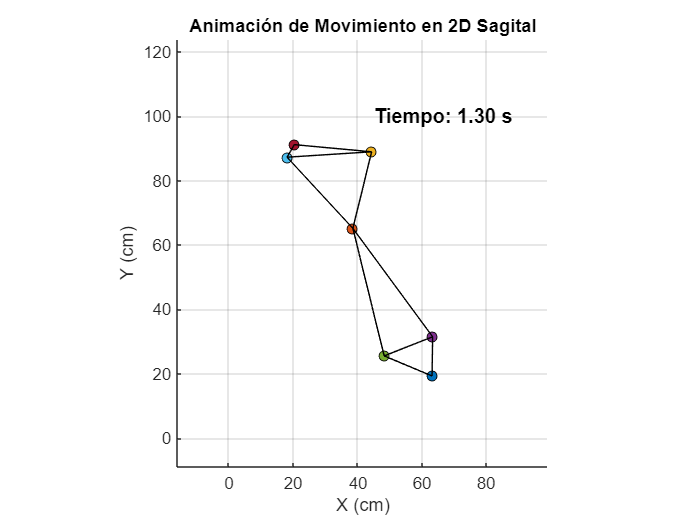

    
    % ========================
    % Animación con las matrices ajustadas
    % ========================
    matrices_a_animar = {'mnk_sag_fixed', 'cod_sag_fixed', ' h_ant_sag_fixed', 'rad_sag_fixed', 'cub_sag_fixed', ...
                         'h_post_sag_fixed', 'esc_sag_fixed'};
    % Aplicar Filtro Pasa-Baja Butterworth a todas las matrices
    fs = 29.97; % Frecuencia de muestreo estimada (ajustar si es necesario)
    fc = 6;   % Frecuencia de corte en Hz
    orden = 4; % Orden del filtro
    [b, a] = butter(orden, fc/(fs/2), 'low'); 
    
    for i = 1:length(matrices_a_animar)
        matriz_nombre = matrices_a_animar{i}; % Obtener el nombre de la matriz
        if isfield(dataStructSagital, matriz_nombre)
            matriz_original = dataStructSagital.(matriz_nombre);
            
            % Aplicar el filtro Butterworth en los ejes X e Y
            matriz_filtrada = matriz_original;
            matriz_filtrada(:, 2) = filtfilt(b, a, matriz_original(:, 2)); % Filtro en X
            matriz_filtrada(:, 3) = filtfilt(b, a, matriz_original(:, 3)); % Filtro en Y
            
            % Guardar la matriz filtrada con el mismo nombre
            dataStructSagital.(matriz_nombre) = matriz_filtrada;
        end
    end
    % Definir colores para cada punto
    colores = lines(length(matrices_a_animar));
    
    % Definir las conexiones (pares de índices de puntos)
    conexiones = [
        1, 4; % mnk con radio
        1, 5; % mnk con cubito
        5, 4; % cubito con radio
        4, 2; % radio con codo
        5, 2; % cubito con codo
        6, 3; % hombro posterior con h_ante
        6, 7; % hombro posterior con escapula
        7, 3; % escapula con h_ante
        3, 2; % h_ante con codo
        6, 2; % hombro posterior con codo
    ];
    
    % Obtener el número de fotogramas de la animación
    num_frames = size(eval(matrices_a_animar{1}), 1); % Todas tienen el mismo número de filas
    
    % Crear figura
    figure;
    hold on;
    xlabel('X (cm)');
    ylabel('Y (cm)');
    title('Animación de Movimiento en 2D Sagital');
    grid on;
    axis equal;
    xlim([-16 99])
    ylim([-9 124])
    % Obtener los datos de cada punto en el primer frame
    puntos = gobjects(size(matrices_a_animar));
    lineas = gobjects(size(conexiones, 1), 1);
    
    for i = 1:length(matrices_a_animar)
        matriz = eval(matrices_a_animar{i});
        puntos(i) = plot(matriz(1, 2), matriz(1, 3), 'o', ...
                         'MarkerFaceColor', colores(i, :), ...
                         'MarkerEdgeColor', 'k', ...
                         'DisplayName', matrices_a_animar{i});
    end
    
    % Crear las líneas iniciales
    for i = 1:size(conexiones, 1)
        idx1 = conexiones(i, 1);
        idx2 = conexiones(i, 2);
    
        matriz2 = eval(matrices_a_animar{idx2});
        lineas(i) = plot([matriz1(1, 2), matriz2(1, 2)], ...
                         [matriz1(1, 3), matriz2(1, 3)], ...
                         '-', 'Color', 'k');
    end
    % Calcular la frecuencia de muestreo
    frame_rate = 1 / 0.033367; % Frecuencia en Hz
    tiempo_texto = text(45, 100, sprintf('Tiempo: %.2f s', 0), ...
                        'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k');
    
    % Animación
    for k = 1:num_frames
        for i = 1:length(matrices_a_animar)
            matriz = eval(matrices_a_animar{i});
            set(puntos(i), 'XData', matriz(k, 2), 'YData', matriz(k, 3)); % Actualizar posición
        end
    
        % Actualizar las líneas
        for i = 1:size(conexiones, 1)
            idx1 = conexiones(i, 1);
            idx2 = conexiones(i, 2);
            matriz1 = eval(matrices_a_animar{idx1});
            matriz2 = eval(matrices_a_animar{idx2});
            set(lineas(i), 'XData', [matriz1(k, 2), matriz2(k, 2)], ...
                           'YData', [matriz1(k, 3), matriz2(k, 3)]);
        end
        
           % Calcular el tiempo exacto en segundos
        tiempo_actual = k / frame_rate;
    
        % Actualizar el texto con el tiempo actual
        set(tiempo_texto, 'String', sprintf('Tiempo: %.2f s', tiempo_actual));
        pause(8*0.033367); % Pausa entre fotogramas para controlar la velocidad
    end
    
    hold off;

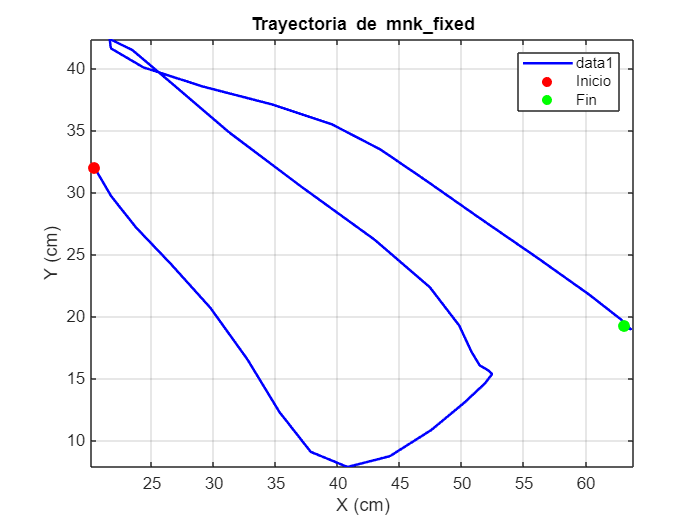

    % Extraer los datos de mnk_fixed
    mnk = dataStructSagital.mnk_sag_fixed; % [Time, X, Y]x
    
    % Extraer tiempo y coordenadas X, Y
    tiempo = mnk(:, 1) / 1000; % Convertir de ms a segundos
    mnkX = mnk(:, 2);
    mnkY = mnk(:, 3);
    
    % Graficar la trayectoria en el tiempo
    figure;
    plot(mnkX, mnkY, 'b', 'LineWidth', 1.5);
    hold on;
    scatter(mnkX(1), mnkY(1), 50, 'r', 'filled', 'DisplayName', 'Inicio'); % Punto inicial
    scatter(mnkX(end), mnkY(end), 50, 'g', 'filled', 'DisplayName', 'Fin'); % Punto final
    title('Trayectoria de mnk\_fixed');
    xlabel('X (cm)');
    ylabel('Y (cm)');
    legend;
    grid on;
    axis equal;
    hold off;

    % Datos de las matrices
    mnk = dataStructSagital.mnk_sag_fixed; % [Time, X, Y]

    radio = dataStructSagital.rad_sag_fixed; % [Time, X, Y]
    cubito = dataStructSagital.cub_sag_fixed; % [Time, X, Y]
    
    % Extraer tiempo, X e Y
    tiempo = mnk(:, 1) / 1000; % Convertir de ms a segundos
    radioX = radio(:, 2);
    radioY = radio(:, 3);
    cubitoX = cubito(:, 2);
    cubitoY = cubito(:, 3);
    mnkX = mnk(:, 2);
    mnkY = mnk(:, 3);
    
    % Calcular los parámetros de la recta entre radio y cubito
    dx = cubitoX - radioX; % Diferencia en X
    dy = cubitoY - radioY; % Diferencia en Y
    
    % Fórmula de la recta: ax + by + c = 0
    a = -dy; % Coeficiente de X
    b = dx;  % Coeficiente de Y
    c = dy .* radioX - dx .* radioY; % Término independiente
    
    % Calcular la distancia de mnk a la recta
    % Fórmula: |a*x + b*y + c| / sqrt(a^2 + b^2)
    distancias = abs(a .* mnkX + b .* mnkY + c) ./ sqrt(a.^2 + b.^2);
    
    % Encontrar el tiempo de máxima y mínima distancia
    [maxDistancia, idxMax] = max(distancias); % Máxima distancia
    [minDistancia, idxMin] = min(distancias); % Mínima distancia
    
    tiempoMax = tiempo(idxMax); % Tiempo de máxima distancia
    tiempoMin = tiempo(idxMin); % Tiempo de mínima distancia
    
    % Mostrar resultados
    fprintf('Máxima distancia: %.3f cm en t = %.3f s\n', maxDistancia, tiempoMax);

Máxima distancia: 13.525 cm en t = 1.101 s


    fprintf('Mínima distancia: %.3f cm en t = %.3f s\n', minDistancia, tiempoMin);

Mínima distancia: 9.529 cm en t = 0.000 s


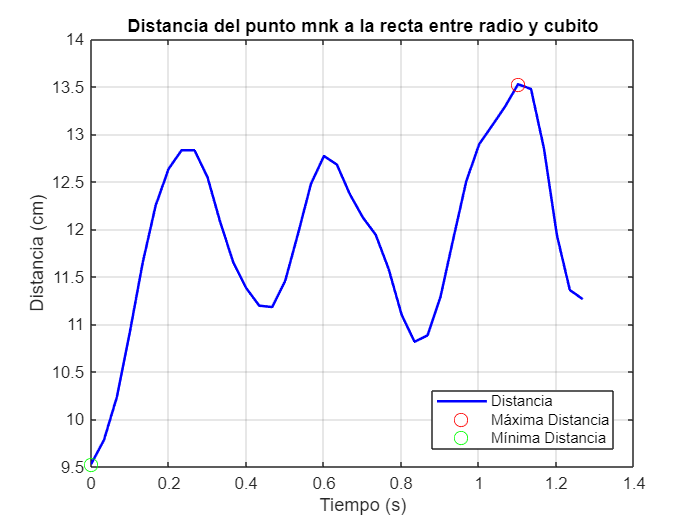

    
    % Graficar la distancia respecto al tiempo
    figure;
    plot(tiempo, distancias, 'b', 'LineWidth', 1.5); hold on;
    plot(tiempo(idxMax), maxDistancia, 'ro', 'MarkerSize', 8, 'DisplayName', 'Máxima Distancia');
    plot(tiempo(idxMin), minDistancia, 'go', 'MarkerSize', 8, 'DisplayName', 'Mínima Distancia');
    title('Distancia del punto mnk a la recta entre radio y cubito');
    xlabel('Tiempo (s)');
    ylabel('Distancia (cm)');
    legend('Distancia', 'Máxima Distancia', 'Mínima Distancia');
    grid on;
    hold off;
    legend(["Distancia", "Máxima Distancia", "Mínima Distancia"], "Position", [0.6169 0.1443 0.2607, 0.1119])

    % Extraer datos de los puntos clave en el plano frontal
    esternon = dataStructFrontal.est_fnt_normXY;  % [Time, X, Y]
    hombro = dataStructFrontal.h_ant_fnt_normXY; % [Time, X, Y]
    codo = dataStructFrontal.cod_fnt_normXY; % [Time, X, Y]
    
    % Convertir tiempo de milisegundos a segundos
    tiempo_abad = esternon(:,1) / 1000; % De ms a s
    times_f=length(tiempo_abad)*1/30.3925707

times_f = 1.2832

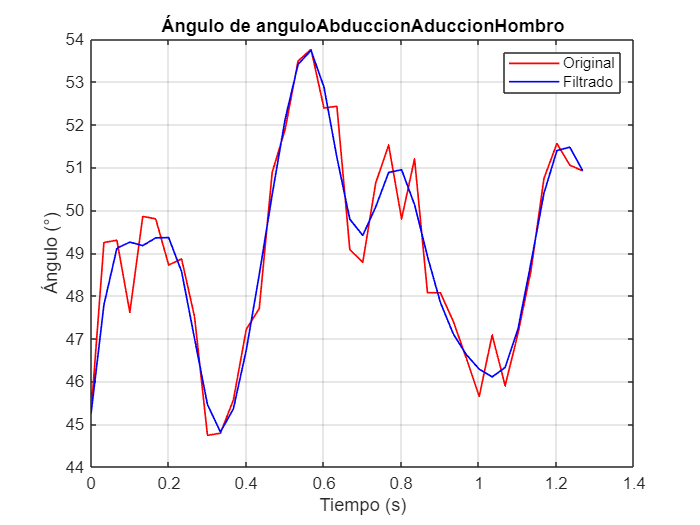

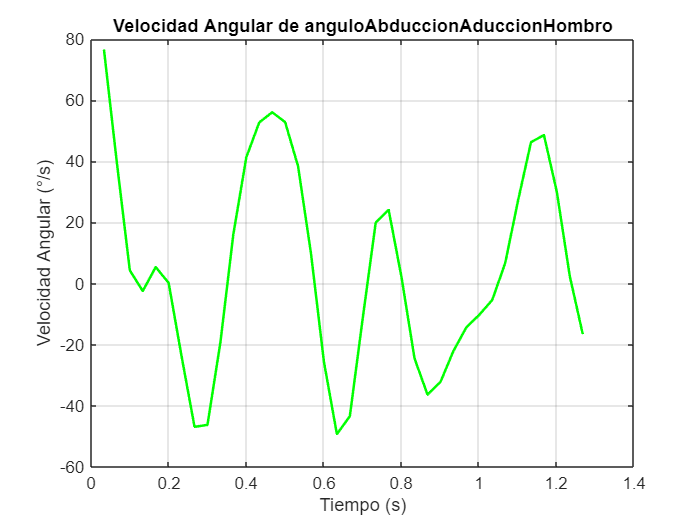

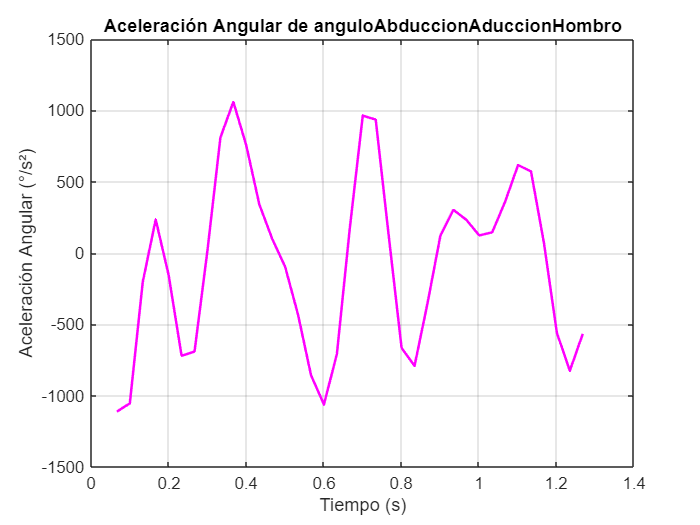

    % Calcular vectores relevantes
    vectorTorsoHombro = hombro(:, 2:3) - esternon(:, 2:3); % (Xh-Xe, Yh-Ye)
    vectorHombroCodo = codo(:, 2:3) - hombro(:, 2:3); % (Xc-Xh, Yc-Yh)
    
    % Normalizar vectores
    vectorTorsoHombro = vectorTorsoHombro ./ vecnorm(vectorTorsoHombro, 2, 2);
    vectorHombroCodo = vectorHombroCodo ./ vecnorm(vectorHombroCodo, 2, 2);
    
    % Calcular el coseno del ángulo usando producto punto
    cosTheta = dot(vectorTorsoHombro, vectorHombroCodo, 2);
    
    % Convertir a grados
    anguloAbduccionAduccionHombro = acosd(cosTheta);
    
    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo2(anguloAbduccionAduccionHombro, tiempo_abad, 'anguloAbduccionAduccionHombro');

anguloAbduccionAduccionHombro - Ángulo:
Máximo: 53.733690° en t = 0.5672333374 s
Mínimo: 44.818726° en t = 0.3336666565 s

anguloAbduccionAduccionHombro - Velocidad Angular:
Máximo: 76.579032°/s en t = 0.0333666649 s
Mínimo: -49.247345°/s en t = 0.6339666748 s

anguloAbduccionAduccionHombro - Aceleración Angular:
Máximo: 1059.360277°/s² en t = 0.3670333252 s
Mínimo: -1111.491276°/s² en t = 0.0667333298 s



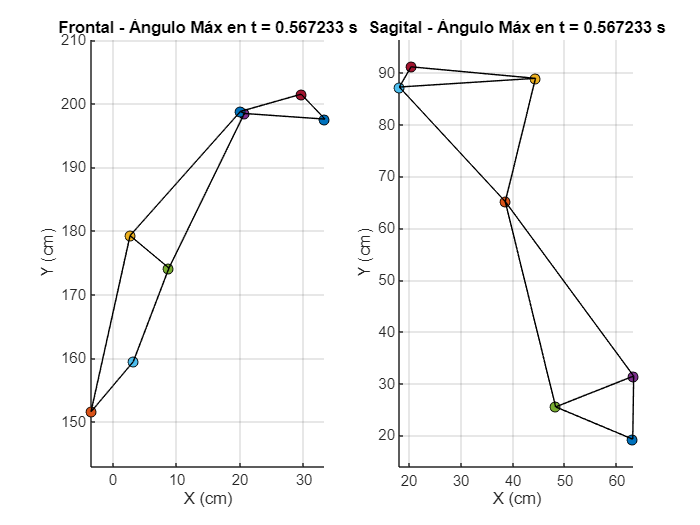

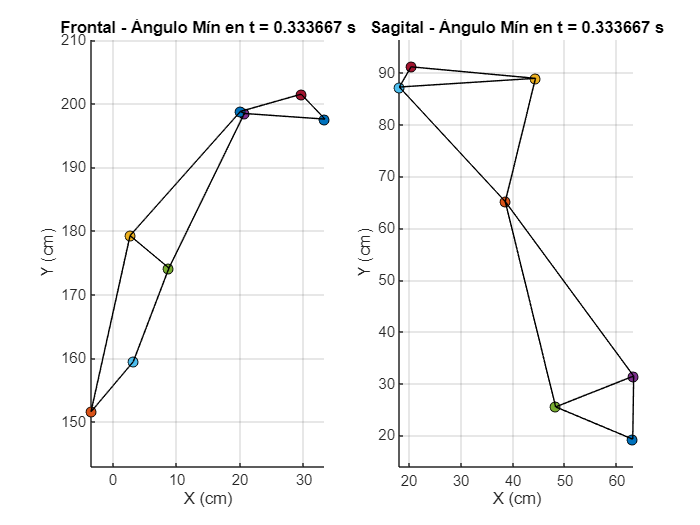

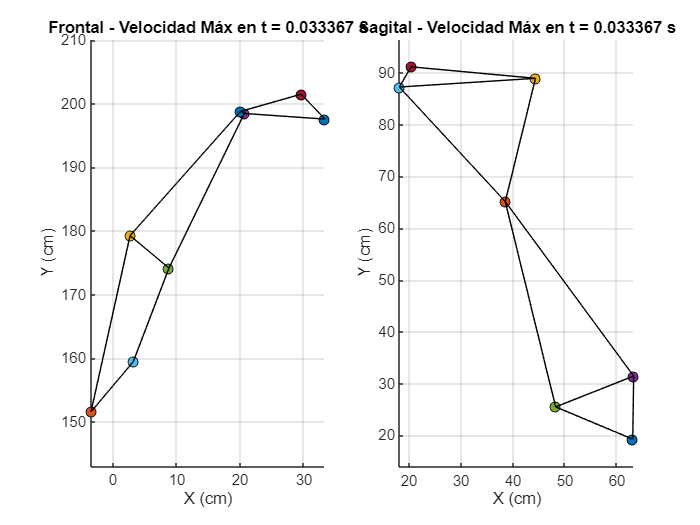

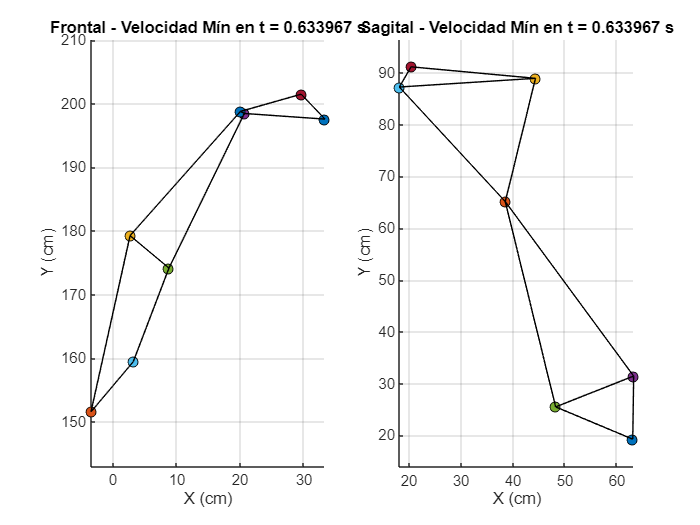

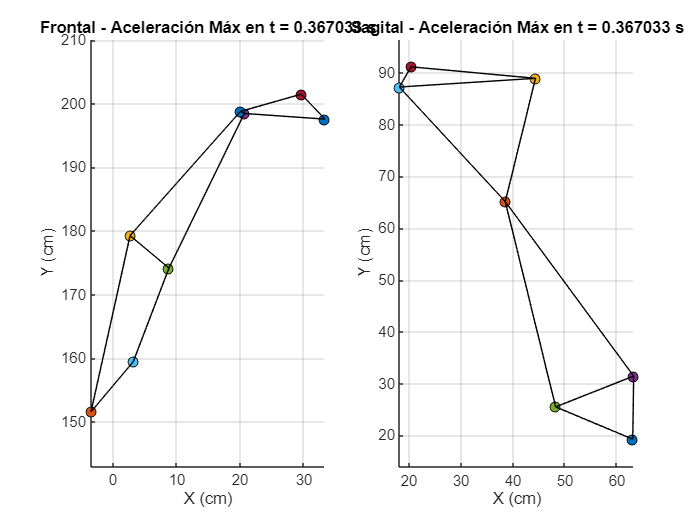

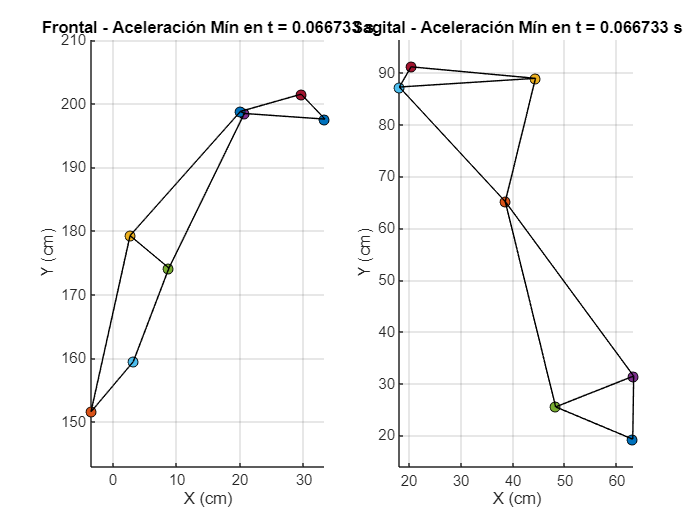

    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo(anguloAbduccionAduccionHombro, tiempo_abad, 'anguloAbduccionAduccionHombro');

    tf_f=ti_f+ times_f;
    

    
        % Extraer datos de los puntos clave en el plano sagital
    hombro = dataStructSagital.h_ant_sag_fixed; % [Time, X, Y]
    codo = dataStructSagital.cod_sag_fixed; % [Time, X, Y]
    
    % Convertir tiempo de milisegundos a segundos
    tiempo_fexh = hombro(:,1) / 1000; % De ms a s
    times_s=length(tiempo_fexh)*1/30.3925707

times_s = 1.2832

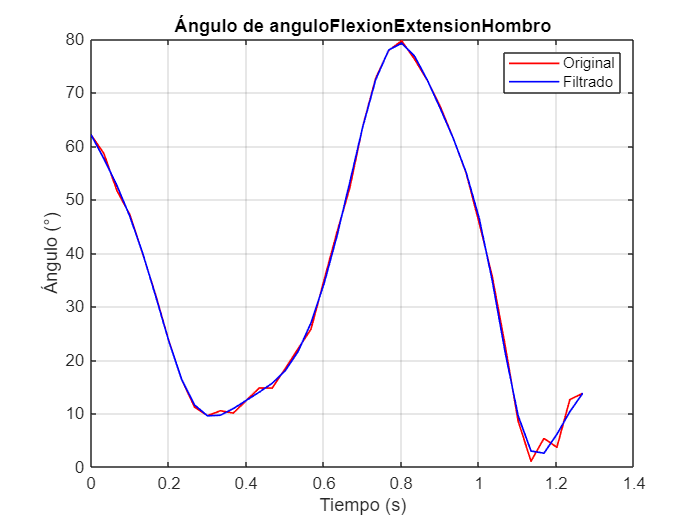

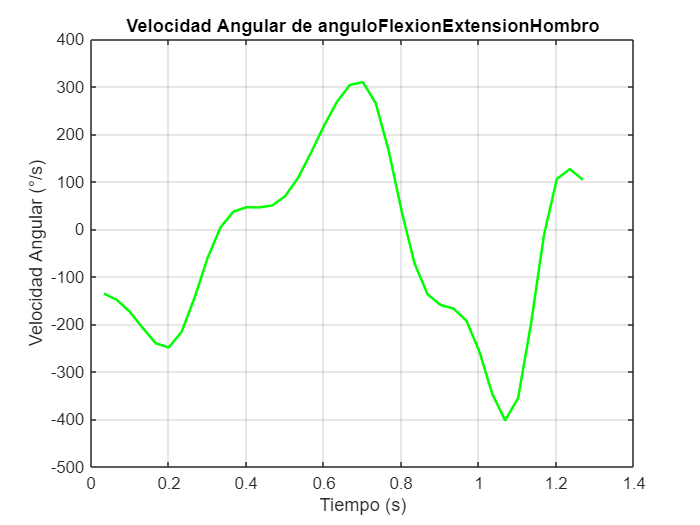

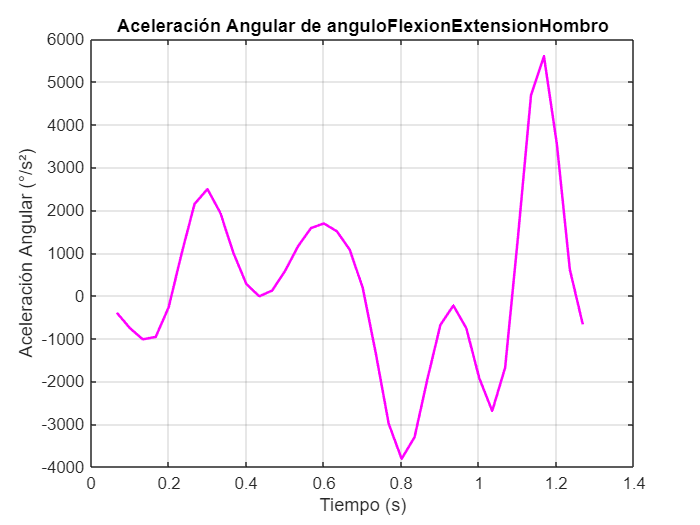

    
    % Definir vector de referencia: línea **vertical** desde el hombro
    vectorReferencia = [zeros(size(hombro,1),1), ones(size(hombro,1),1)]; % (0,1) es vertical
    
    % Calcular el vector hombro-codo
    vectorHombroCodo = codo(:, 2:3) - hombro(:, 2:3); % (Xc-Xh, Yc-Yh)
    
    % Normalizar vectores
    vectorHombroCodo = vectorHombroCodo ./ vecnorm(vectorHombroCodo, 2, 2);
    vectorReferencia = vectorReferencia ./ vecnorm(vectorReferencia, 2, 2);
    
    % Calcular el coseno del ángulo usando producto punto
    cosTheta = dot(vectorReferencia, vectorHombroCodo, 2);
    
    % Convertir a grados
    anguloFlexionExtensionHombro = 180-   acosd(cosTheta);
    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo2(anguloFlexionExtensionHombro, tiempo_fexh, 'anguloFlexionExtensionHombro');

anguloFlexionExtensionHombro - Ángulo:
Máximo: 79.212912° en t = 0.8007999878 s
Mínimo: 2.581833° en t = 1.1678333740 s

anguloFlexionExtensionHombro - Velocidad Angular:
Máximo: 309.418333°/s en t = 0.7007000122 s
Mínimo: -401.932548°/s en t = 1.0677332764 s

anguloFlexionExtensionHombro - Aceleración Angular:
Máximo: 5597.560311°/s² en t = 1.1678333740 s
Mínimo: -3808.838797°/s² en t = 0.8007999878 s



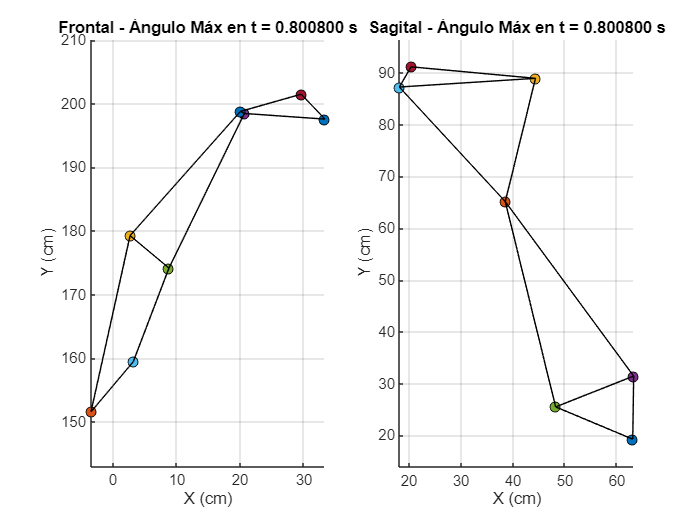

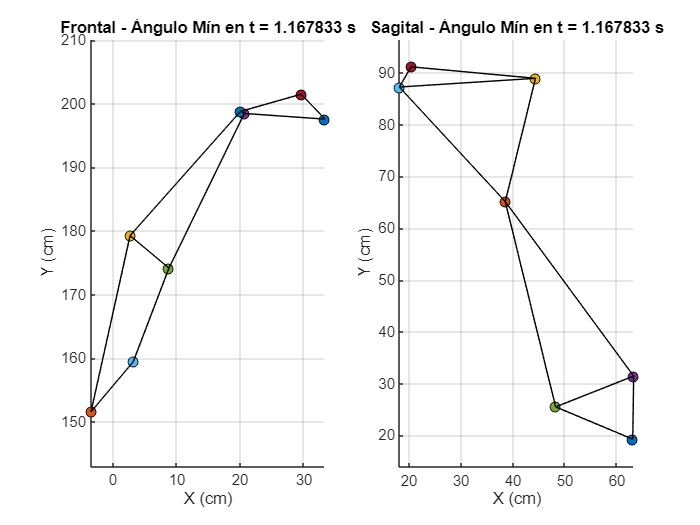

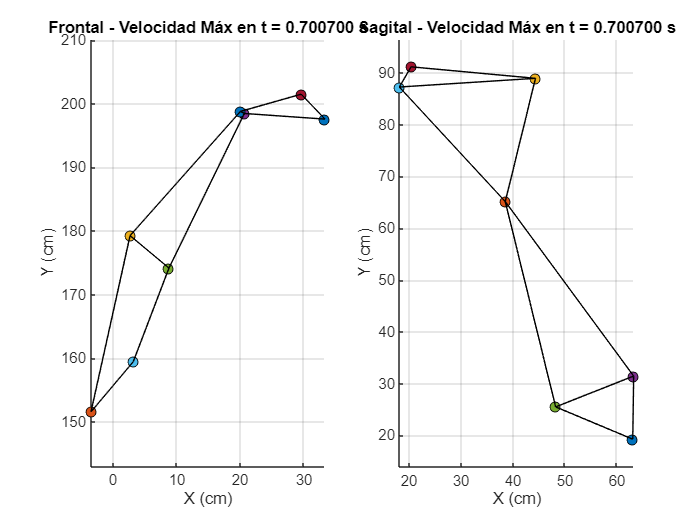

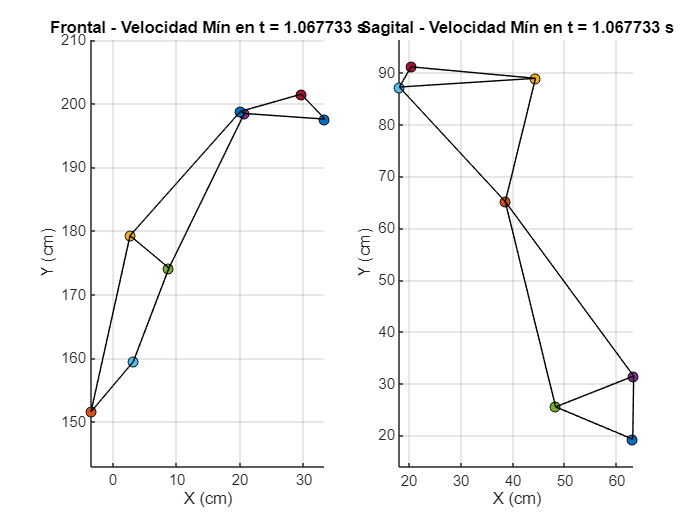

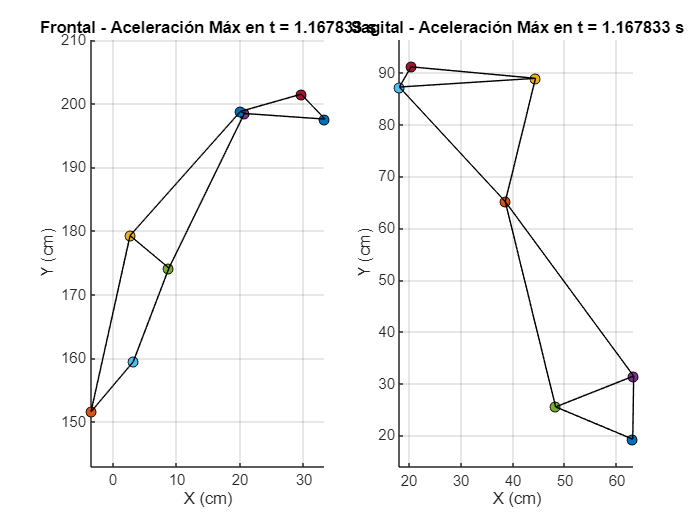

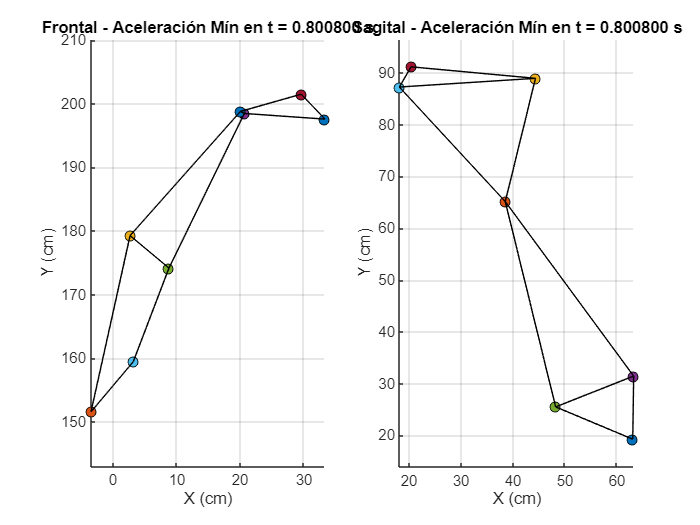

    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo(anguloFlexionExtensionHombro, tiempo_fexh, 'anguloFlexionExtensionHombro');

    tf_s=ti_s+times_s;

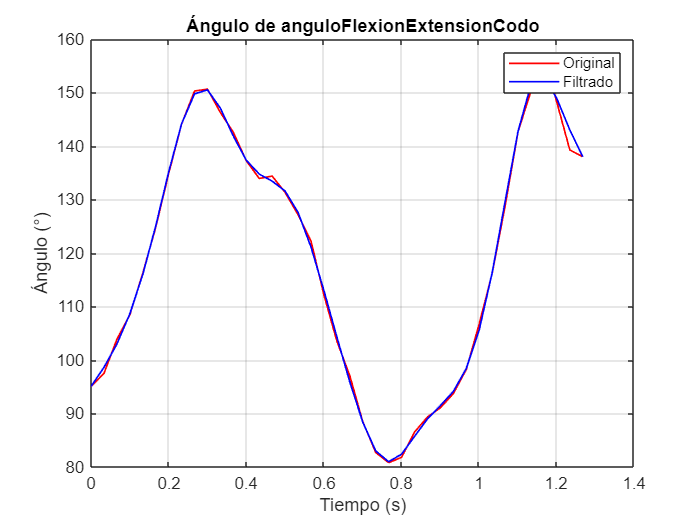

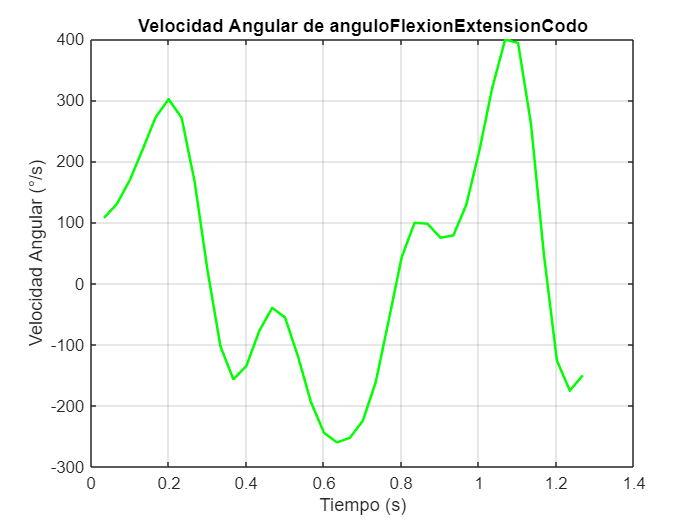

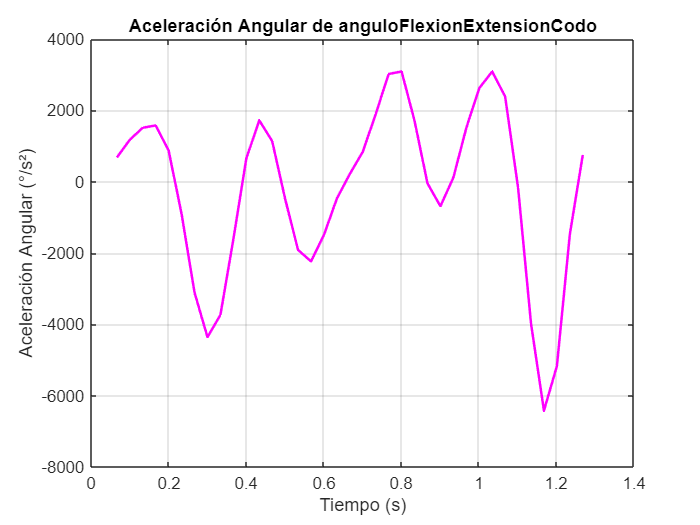

    % Extraer datos de los puntos clave en el plano sagital
    hombro = dataStructSagital.h_ant_sag_fixed; % [Time, X, Y]
    codo = dataStructSagital.cod_sag_fixed; % [Time, X, Y]
    muneca = dataStructSagital.mnk_sag_fixed; % [Time, X, Y]
    
    % Convertir tiempo de milisegundos a segundos
    tiempo_fck = hombro(:,1) / 1000; % De ms a s
    
    % Calcular los vectores
    vectorHombroCodo = codo(:, 2:3) - hombro(:, 2:3); % (Xc-Xh, Yc-Yh)
    vectorCodoMuneca = muneca(:, 2:3) - codo(:, 2:3); % (Xm-Xc, Ym-Yc)
    
    % Normalizar los vectores
    vectorHombroCodo = vectorHombroCodo ./ vecnorm(vectorHombroCodo, 2, 2);
    vectorCodoMuneca = vectorCodoMuneca ./ vecnorm(vectorCodoMuneca, 2, 2);
    
    % Calcular el coseno del ángulo usando producto punto
    cosTheta = dot(vectorHombroCodo, vectorCodoMuneca, 2);
    
    % Convertir a grados
    anguloFlexionExtensionCodo = 180-acosd(cosTheta);
    
    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo2(anguloFlexionExtensionCodo, tiempo_fck, 'anguloFlexionExtensionCodo');

anguloFlexionExtensionCodo - Ángulo:
Máximo: 153.034413° en t = 1.1678333740 s
Mínimo: 80.985677° en t = 0.7674333496 s

anguloFlexionExtensionCodo - Velocidad Angular:
Máximo: 399.219581°/s en t = 1.0677332764 s
Mínimo: -259.676696°/s en t = 0.6339666748 s

anguloFlexionExtensionCodo - Aceleración Angular:
Máximo: 3089.477146°/s² en t = 0.8007999878 s
Mínimo: -6419.243116°/s² en t = 1.1678333740 s



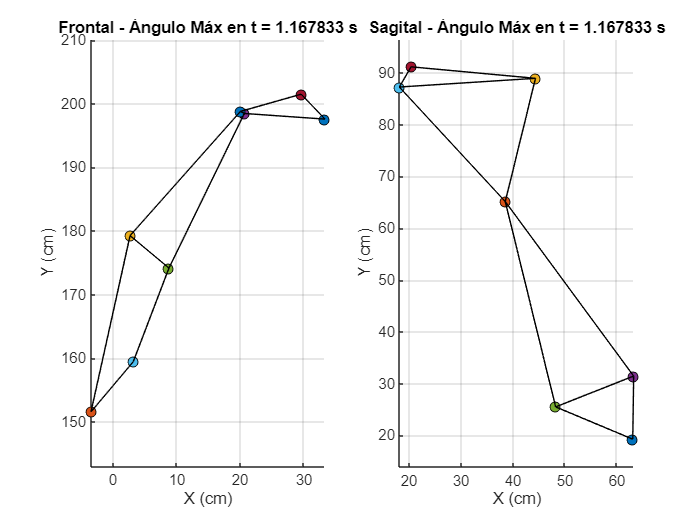

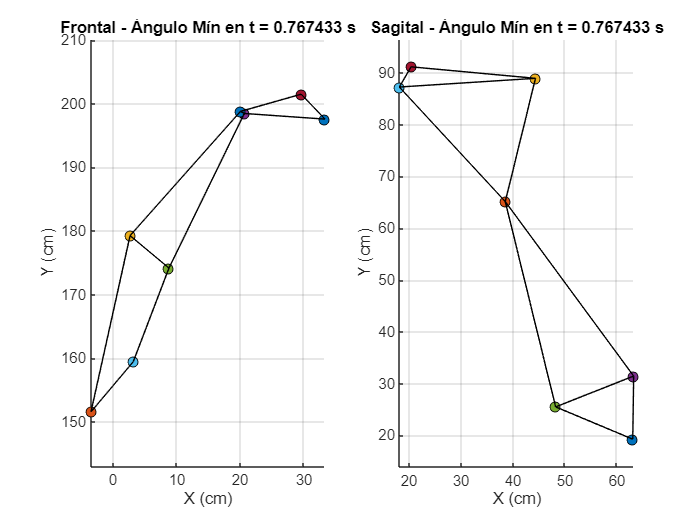

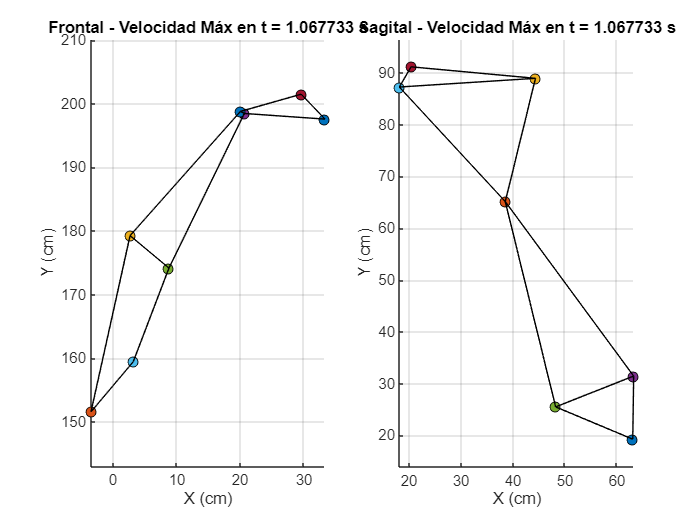

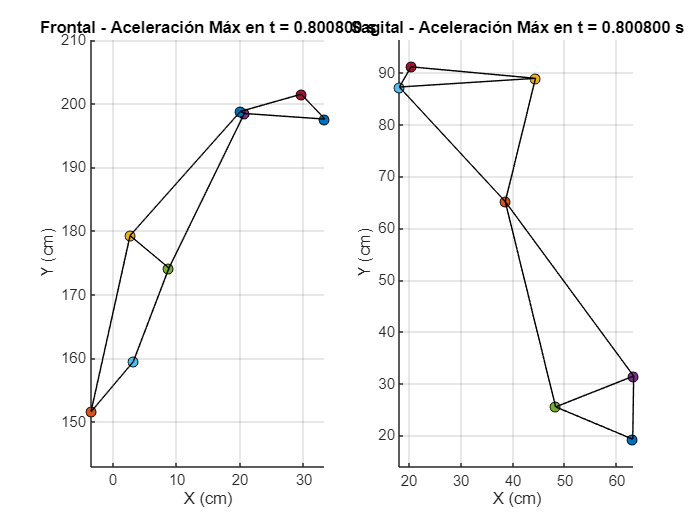

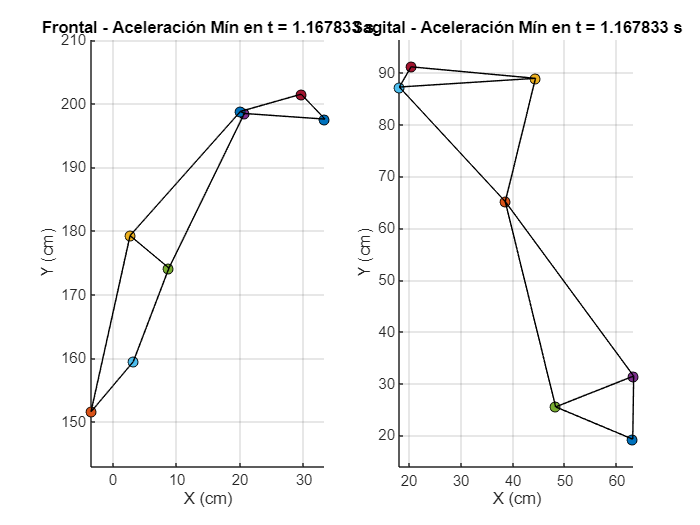

    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo(anguloFlexionExtensionCodo, tiempo_fck, 'anguloFlexionExtensionCodo');

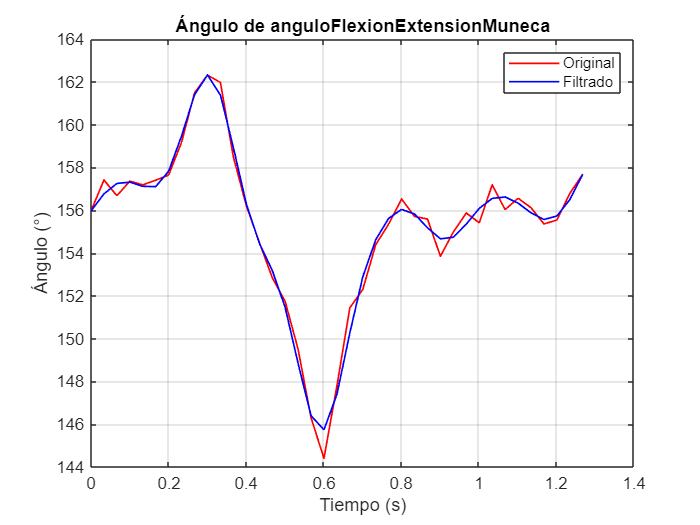

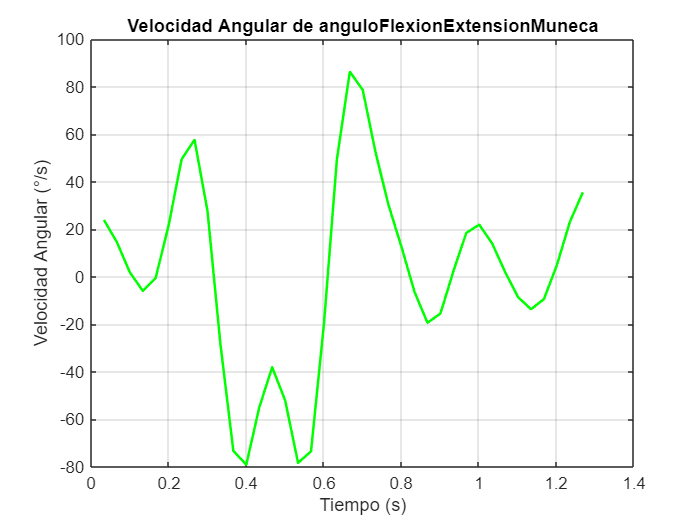

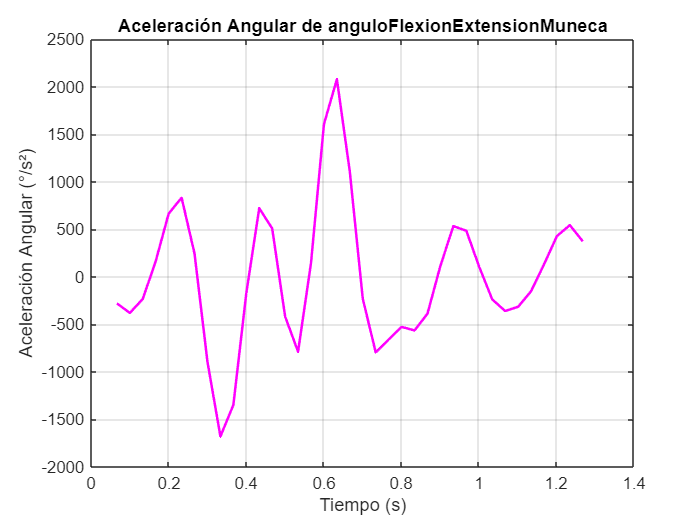

    % Extraer datos de los puntos clave en el plano sagital
    codo = dataStructFrontal.cod_fnt_normXY; % [Time, X, Y]
    codoMedial = dataStructFrontal.cod_med_fnt_normXY; % [Time, X, Y]
    radio = dataStructFrontal.rad_fnt_normXY; % [Time, X, Y]
    
    % Convertir tiempo de milisegundos a segundos
    tiempo_fenk = codo(:,1) / 1000; % De ms a s
    
    % Calcular los vectores
    vectorCodoRadio = radio(:, 2:3) - codo(:, 2:3); % (Xr-Xc, Yr-Yc)
    vectorCodoMedialRadio = radio(:, 2:3) - codoMedial(:, 2:3); % (Xr-Xcm, Yr-Ycm)
    
    % Normalizar los vectores
    vectorCodoRadio = vectorCodoRadio ./ vecnorm(vectorCodoRadio, 2, 2);
    vectorCodoMedialRadio = vectorCodoMedialRadio ./ vecnorm(vectorCodoMedialRadio, 2, 2);
    
    % Calcular el coseno del ángulo usando producto punto
    cosTheta = dot(vectorCodoRadio, vectorCodoMedialRadio, 2);
    
    % Convertir a grados y ajustar a ángulo mayor a 90°
    anguloFlexionExtensionMuneca = 180 - acosd(cosTheta);
    
    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo2(anguloFlexionExtensionMuneca, tiempo_fenk, 'anguloFlexionExtensionMuneca');

anguloFlexionExtensionMuneca - Ángulo:
Máximo: 162.320698° en t = 0.3002999878 s
Mínimo: 145.737233° en t = 0.6005999756 s

anguloFlexionExtensionMuneca - Velocidad Angular:
Máximo: 86.234414°/s en t = 0.6673333130 s
Mínimo: -79.009662°/s en t = 0.4003999939 s

anguloFlexionExtensionMuneca - Aceleración Angular:
Máximo: 2076.380197°/s² en t = 0.6339666748 s
Mínimo: -1678.386571°/s² en t = 0.3336666565 s



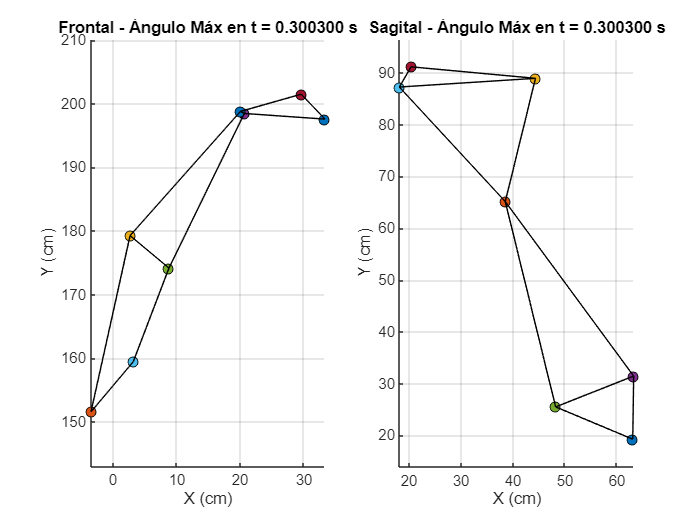

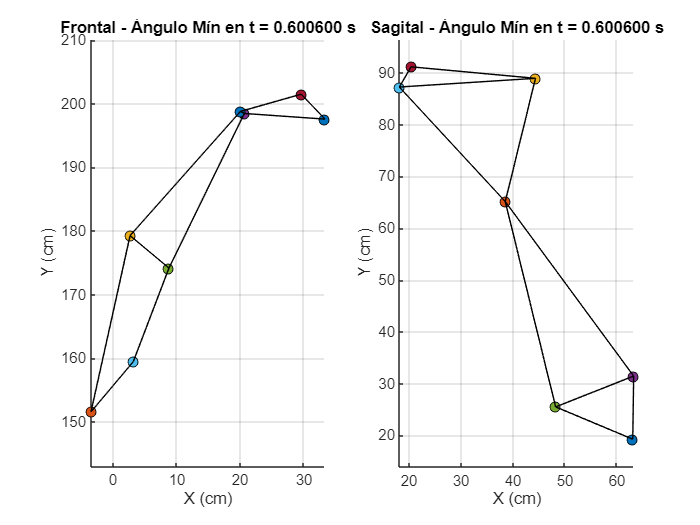

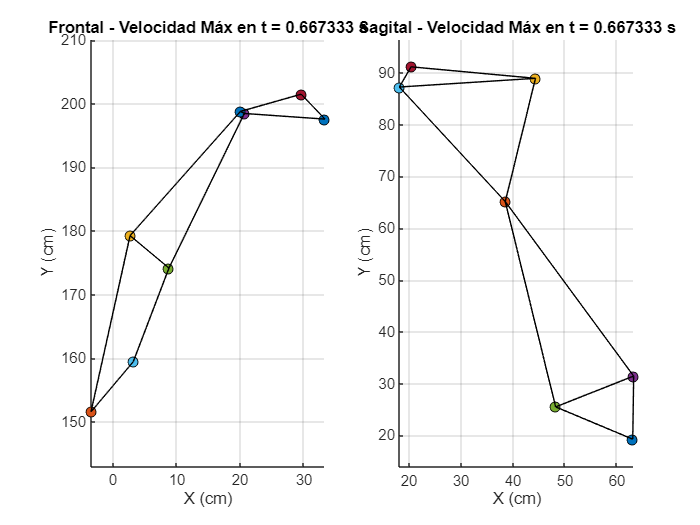

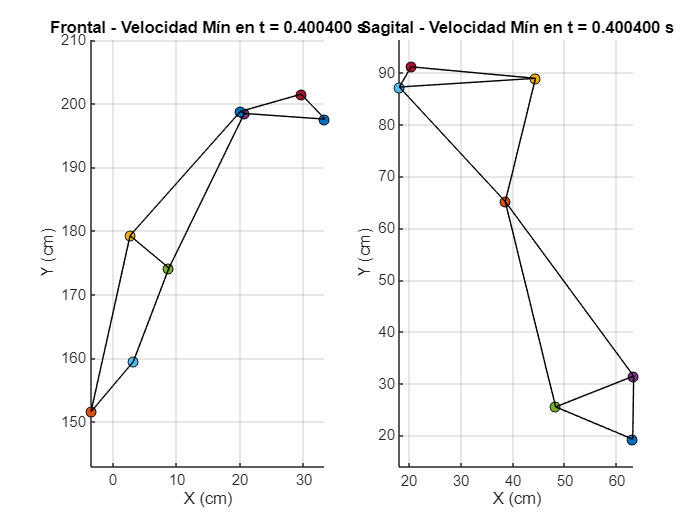

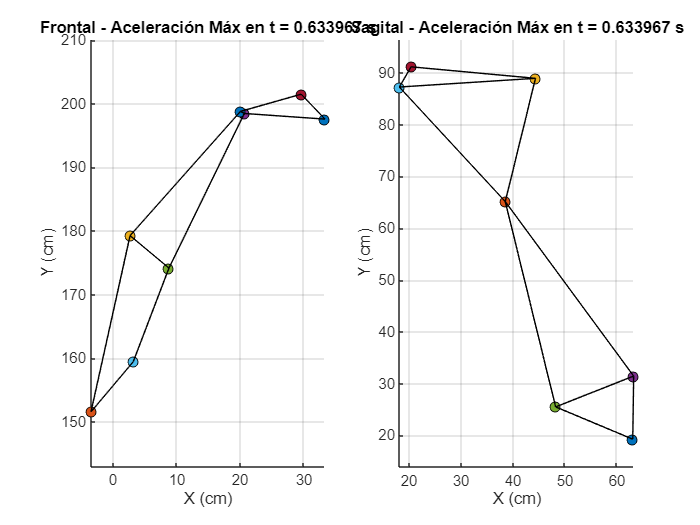

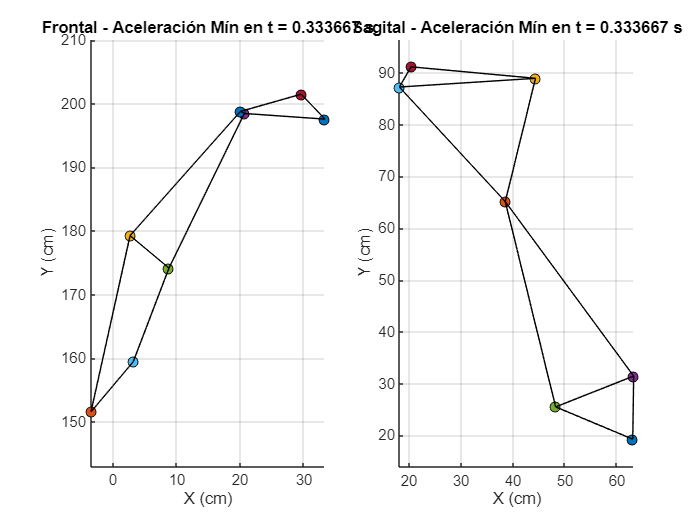

    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo(anguloFlexionExtensionMuneca, tiempo_fenk, 'anguloFlexionExtensionMuneca');

    % Datos de las matrices
    mnk = dataStructSagital.mnk_sag_fixed; % [Time, X, Y]
    radio = dataStructSagital.rad_sag_fixed; % [Time, X, Y]
    cubito = dataStructSagital.cub_sag_fixed; % [Time, X, Y]
    
    % Extraer tiempo, X e Y
    tiempo_dk = mnk(:, 1) / 1000; % Convertir de ms a segundos
    radioX = radio(:, 2);
    radioY = radio(:, 3);
    cubitoX = cubito(:, 2);
    cubitoY = cubito(:, 3);
    mnkX = mnk(:, 2);
    mnkY = mnk(:, 3);
    
    % Calcular los parámetros de la recta entre radio y cubito
    dx = cubitoX - radioX; % Diferencia en X
    dy = cubitoY - radioY; % Diferencia en Y
    
    % Fórmula de la recta: ax + by + c = 0
    a = -dy; % Coeficiente de X
    b = dx;  % Coeficiente de Y
    c = dy .* radioX - dx .* radioY; % Término independiente
    
    % Calcular la distancia de mnk a la recta
    % Fórmula: |a*x + b*y + c| / sqrt(a^2 + b^2)
    distancias = abs(a .* mnkX + b .* mnkY + c) ./ sqrt(a.^2 + b.^2);
    
    % Encontrar el tiempo de máxima y mínima distancia
    [maxDistancia, idxMax] = max(distancias); % Máxima distancia
    [minDistancia, idxMin] = min(distancias); % Mínima distancia
    
    tiempoMax = tiempo_dk(idxMax); % Tiempo de máxima distancia
    tiempoMin = tiempo_dk(idxMin); % Tiempo de mínima distancia
    
    % Mostrar resultados de distancias
    fprintf('Máxima distancia: %.3f cm en t = %.3f s\n', maxDistancia, tiempoMax);

Máxima distancia: 13.525 cm en t = 1.101 s


    fprintf('Mínima distancia: %.3f cm en t = %.3f s\n', minDistancia, tiempoMin);

Mínima distancia: 9.529 cm en t = 0.000 s


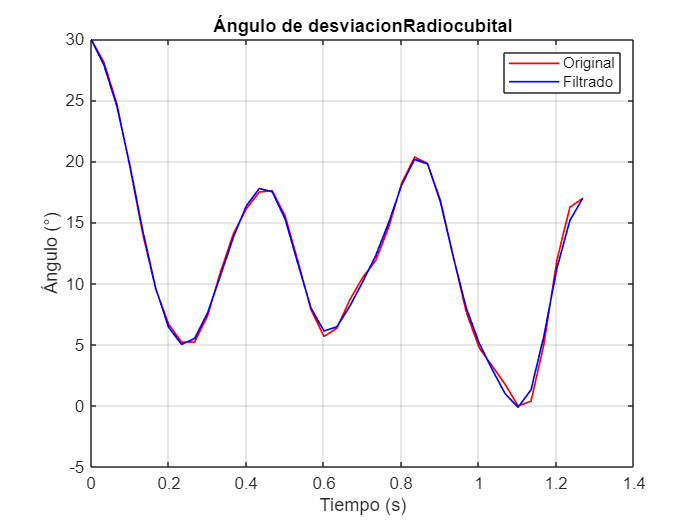

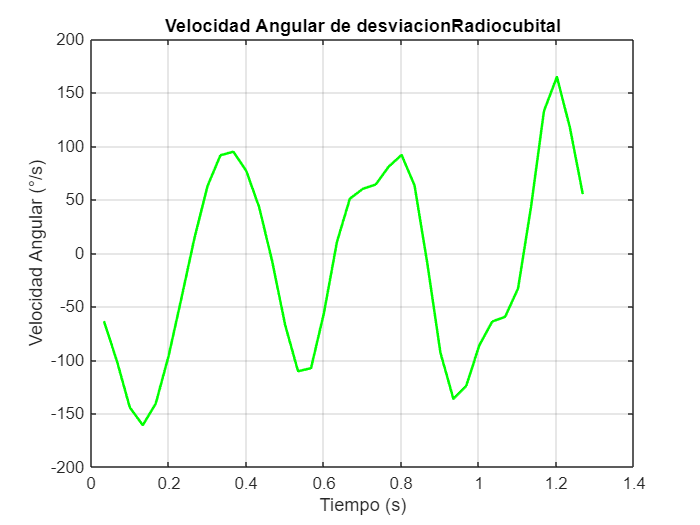

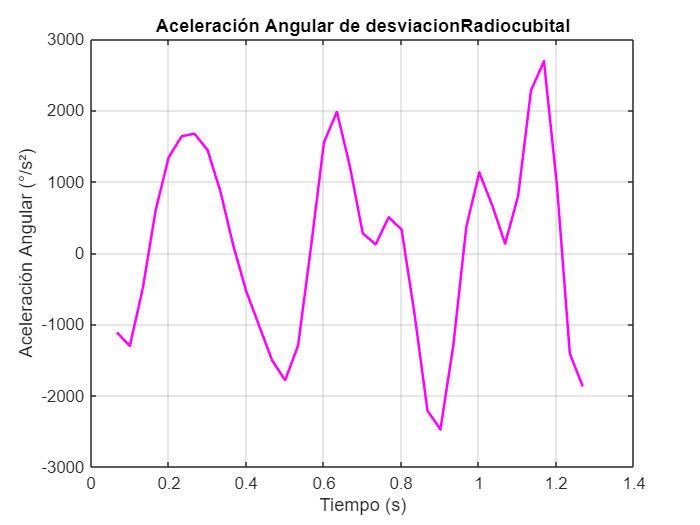

    
    % Calcular la desviación radiocubital
    % Escalar las distancias usando una regla de tres (invertida)
    desviacionRadiocubital = 30 * (maxDistancia - distancias) / (maxDistancia - minDistancia);
    [velocidad, aceleracion, anguloFiltrado] = procesarAngulo2(desviacionRadiocubital, tiempo_dk, 'desviacionRadiocubital');

desviacionRadiocubital - Ángulo:
Máximo: 29.995044° en t = 0.0000000000 s
Mínimo: -0.116425° en t = 1.1010999756 s

desviacionRadiocubital - Velocidad Angular:
Máximo: 164.552934°/s en t = 1.2012000389 s
Mínimo: -160.889156°/s en t = 0.1334666595 s

desviacionRadiocubital - Aceleración Angular:
Máximo: 2686.981206°/s² en t = 1.1678333740 s
Mínimo: -2472.562537°/s² en t = 0.9009000244 s



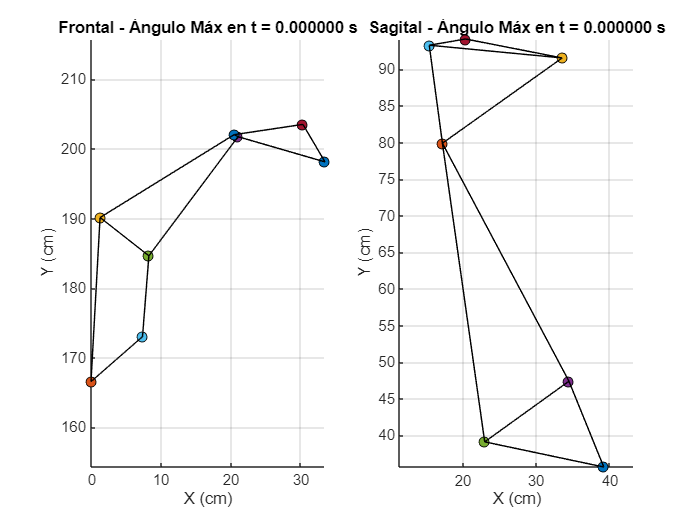

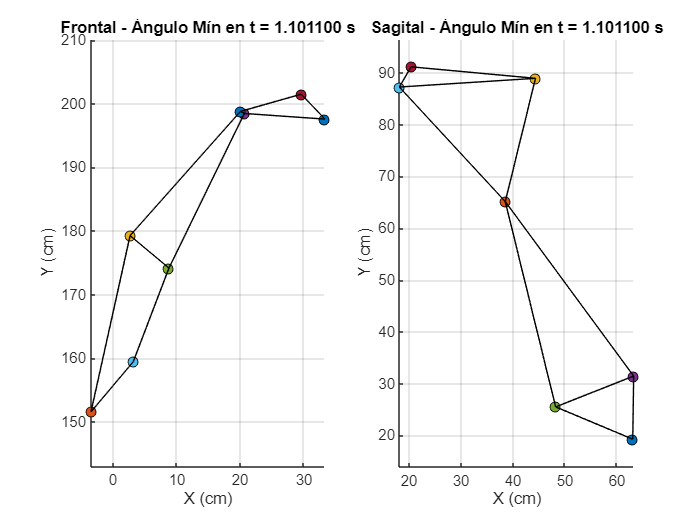

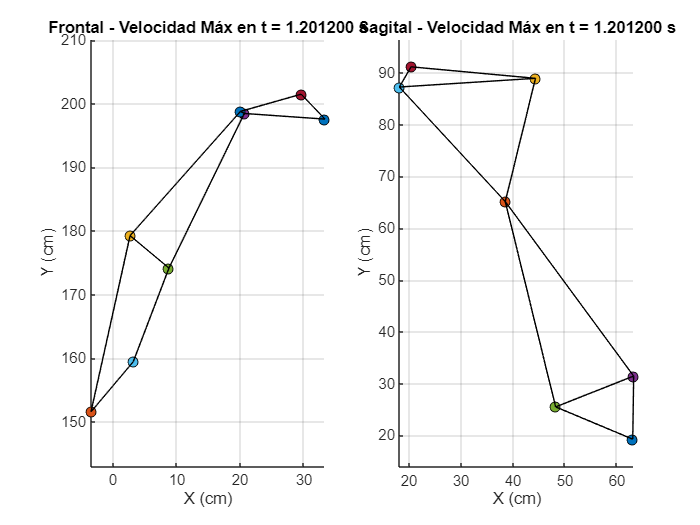

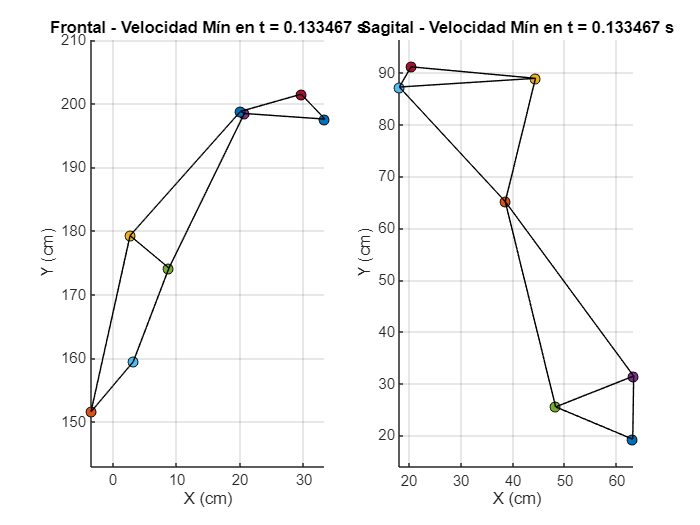

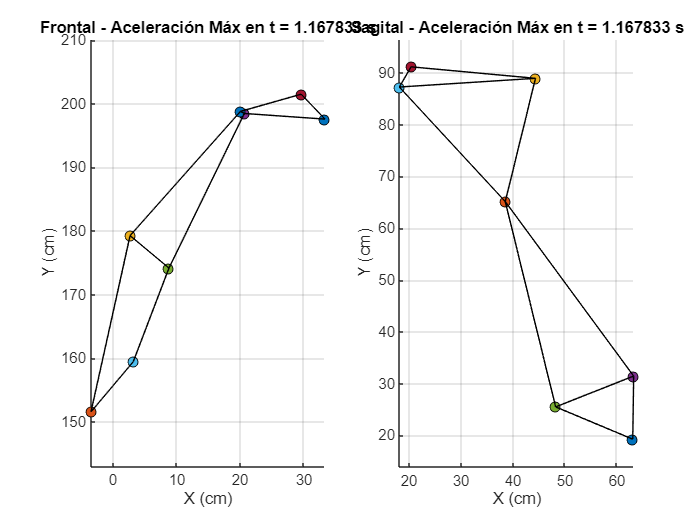

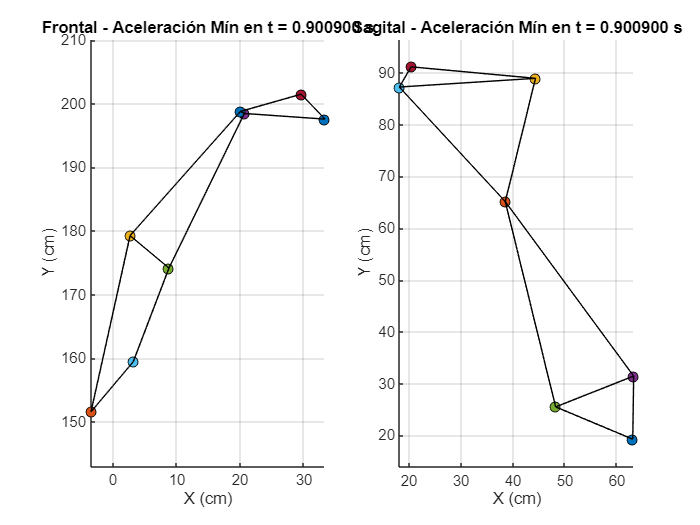

     [velocidad, aceleracion, anguloFiltrado] = procesarAngulo(desviacionRadiocubital, tiempo_dk, 'desviacionRadiocubital');

    % Nombre del archivo
    filename = isen;
    
    % Verificar si el archivo existe
    if exist(filename, 'file') == 2
        % Leer el archivo CSV
        dataTable = readtable(filename, 'Delimiter', ',', 'PreserveVariableNames', true);
    
        % Reemplazar espacios y caracteres inválidos en los nombres de las columnas
        columnNames = dataTable.Properties.VariableNames;
        for i = 1:length(columnNames)
            columnNames{i} = matlab.lang.makeValidName(strrep(columnNames{i}, ' ', '_'));
        end
        dataTable.Properties.VariableNames = columnNames;
    
        % Mostrar información general del archivo
        fprintf('Información del archivo: %s\n', filename);
        fprintf('Número de filas: %d\n', height(dataTable));
        fprintf('Número de columnas: %d\n', width(dataTable));
    
        % Mostrar los primeros 5 registros para inspección
        disp('Primeras 5 filas de los datos:');
        disp(head(dataTable, 5));
    
        % Mostrar los nombres de las columnas corregidos
        disp('Nombres de las columnas corregidos:');
        disp(columnNames);
    
        % Verificar si hay valores NaN en los datos
        missingData = sum(ismissing(dataTable));
        fprintf('Número de valores faltantes por columna:\n');
        disp(array2table(missingData, 'VariableNames', columnNames));
    
        % Guardar cada columna en el workspace con su nombre correspondiente
        for i = 1:length(columnNames)
            variableName = columnNames{i}; % Nombre corregido de la columna
            assignin('base', variableName, dataTable.(variableName)); % Guardar en el workspace
            fprintf('Matriz guardada en workspace: %s\n', variableName);
        end
    else
        fprintf('El archivo "%s" no existe en el directorio actual.\n', filename);
    end

Información del archivo: C:\Users\fabia\Desktop\DPB4\Datos Reales\1. Primer voluntario (Alfonso)\Toma 5\VOLUNTARIO_1.csv


Número de filas: 1070


Número de columnas: 11


Primeras 5 filas de los datos:


    Tiempo    Flexo_extensi_n_hombro_derecho_X    Flexo_extensi_n_hombro_derecho_Y    Abducci_n_aducci_n_hombro_derecho_X    Abducci_n_aducci_n_hombro_derecho_Y    Flexo_extensi_n_codo_derecho_X    Flexo_extensi_n_codo_derecho_Y    Flexo_extensi_n_mu_eca_derecha_X    Flexo_extensi_n_mu_eca_derecha_Y    Desviaci_n_radiocubital_mu_eca_derecha_X    Desviaci_n_radiocubital_mu_eca_derecha_Y
    ______    ________________________________    ________________________________    ___________________________________    ___________________________________    ______________________________    ______________________________    ________________________________    ____________

Nombres de las columnas corregidos:


    {'Tiempo'}    {'Flexo_extensi_n_hombro_derecho_X'}    {'Flexo_extensi_n_hombro_derecho_Y'}    {'Abducci_n_aducci_n_hombro_derecho_X'}    {'Abducci_n_aducci_n_hombro_derecho_Y'}    {'Flexo_extensi_n_codo_derecho_X'}    {'Flexo_extensi_n_codo_derecho_Y'}    {'Flexo_extensi_n_mu_eca_derecha_X'}    {'Flexo_extensi_n_mu_eca_derecha_Y'}    {'Desviaci_n_radiocubital_mu_eca_derecha_X'}    {'Desviaci_n_radiocubital_mu_eca_derecha_Y'}



Número de valores faltantes por columna:


    Tiempo    Flexo_extensi_n_hombro_derecho_X    Flexo_extensi_n_hombro_derecho_Y    Abducci_n_aducci_n_hombro_derecho_X    Abducci_n_aducci_n_hombro_derecho_Y    Flexo_extensi_n_codo_derecho_X    Flexo_extensi_n_codo_derecho_Y    Flexo_extensi_n_mu_eca_derecha_X    Flexo_extensi_n_mu_eca_derecha_Y    Desviaci_n_radiocubital_mu_eca_derecha_X    Desviaci_n_radiocubital_mu_eca_derecha_Y
    ______    ________________________________    ________________________________    ___________________________________    ___________________________________    ______________________________    ______________________________    ________________________________    ____________

Matriz guardada en workspace: Tiempo
Matriz guardada en workspace: Flexo_extensi_n_hombro_derecho_X
Matriz guardada en workspace: Flexo_extensi_n_hombro_derecho_Y
Matriz guardada en workspace: Abducci_n_aducci_n_hombro_derecho_X
Matriz guardada en workspace: Abducci_n_aducci_n_hombro_derecho_Y
Matriz guardada en workspace: Flexo_extensi_n_codo_derecho_X
Matriz guardada en workspace: Flexo_extensi_n_codo_derecho_Y
Matriz guardada en workspace: Flexo_extensi_n_mu_eca_derecha_X
Matriz guardada en workspace: Flexo_extensi_n_mu_eca_derecha_Y
Matriz guardada en workspace: Desviaci_n_radiocubital_mu_eca_derecha_X
Matriz guardada en workspace: Desviaci_n_radiocubital_mu_eca_derecha_Y


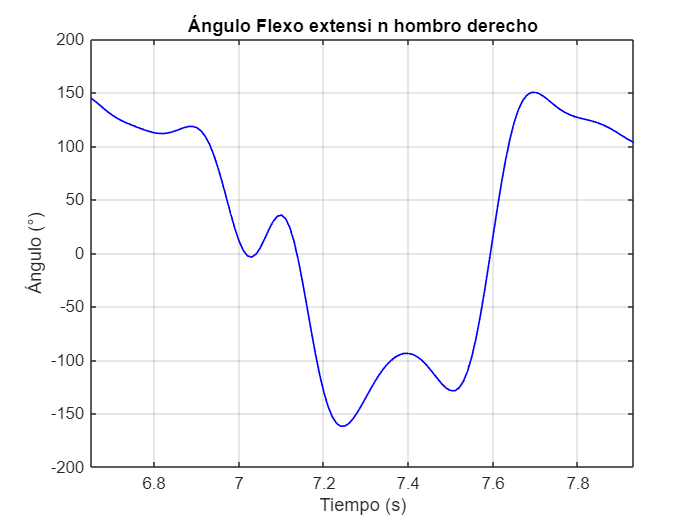

Ángulo [Flexo_extensi_n_hombro_derecho]: Máximo: 207.65°, Mínimo: -203.09°


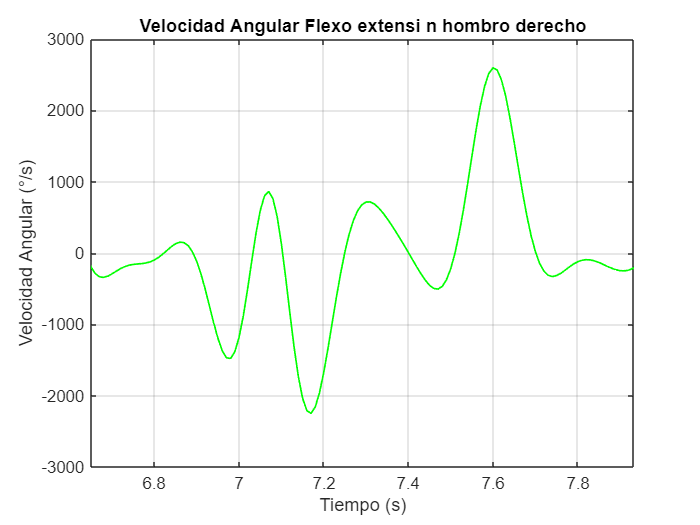

Velocidad Angular [Flexo_extensi_n_hombro_derecho]: Máximo: 4023.69°/s, Mínimo: -4047.05°/s


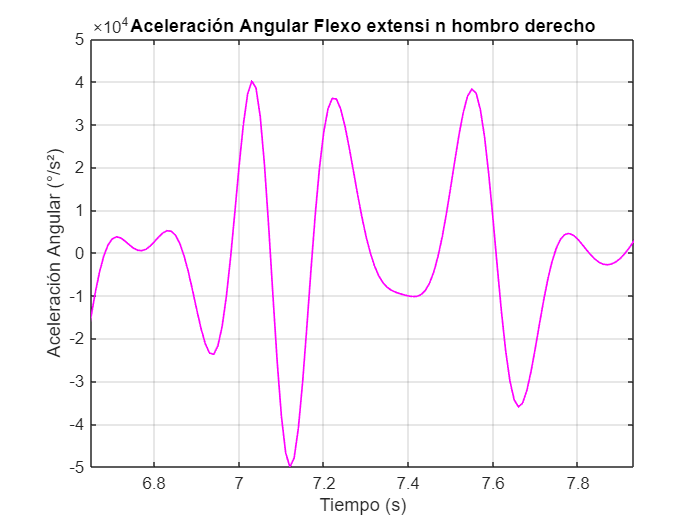

Aceleración Angular [Flexo_extensi_n_hombro_derecho]: Máximo: 99154.02°/s², Mínimo: -85639.23°/s²


    procesar_isen(Tiempo, Flexo_extensi_n_hombro_derecho_X, Flexo_extensi_n_hombro_derecho_Y,ti_s,tf_s);

    comparar_kinovea_isen(anguloFlexionExtensionHombro_filtrado, tiempo_fexh, Flexo_extensi_n_hombro_derecho_angulo, tiempo_Flexo_extensi_n_hombro_derecho, ti_s, tf_s);

📊 Resultados de Kinovea (anguloFlexionExtensionHombro_filtrado - todo el rango):
   Media: 35.53°
   STD: 24.63°
   Máx: 79.21°
   Mín: 2.58°
   Rango: 76.63°

📊 Resultados de iSen (anguloFlexionExtensionHombro_filtrado - intervalo [6.65, 7.93] s):
   Media: 24.32°
   STD: 107.43°
   Máx: 150.20°
   Mín: -161.88°
   Rango: 312.08°



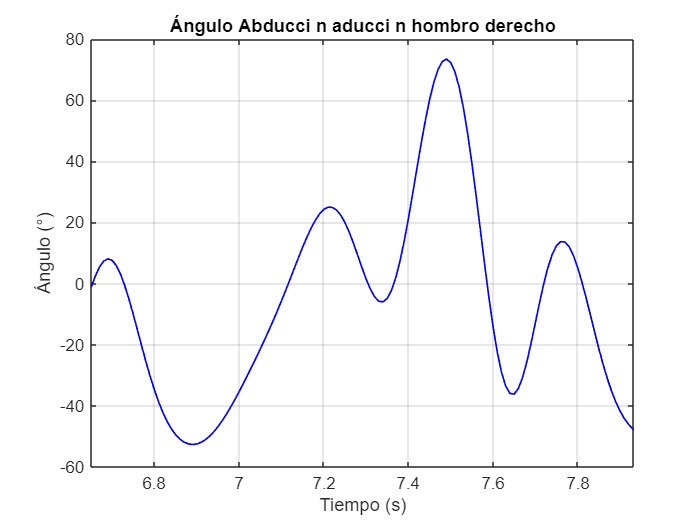

Ángulo [Abducci_n_aducci_n_hombro_derecho]: Máximo: 73.42°, Mínimo: -56.68°


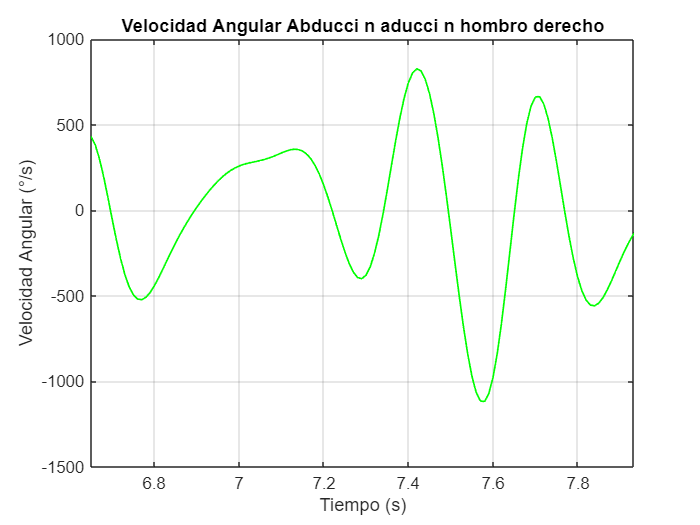

Velocidad Angular [Abducci_n_aducci_n_hombro_derecho]: Máximo: 825.91°/s, Mínimo: -1117.85°/s


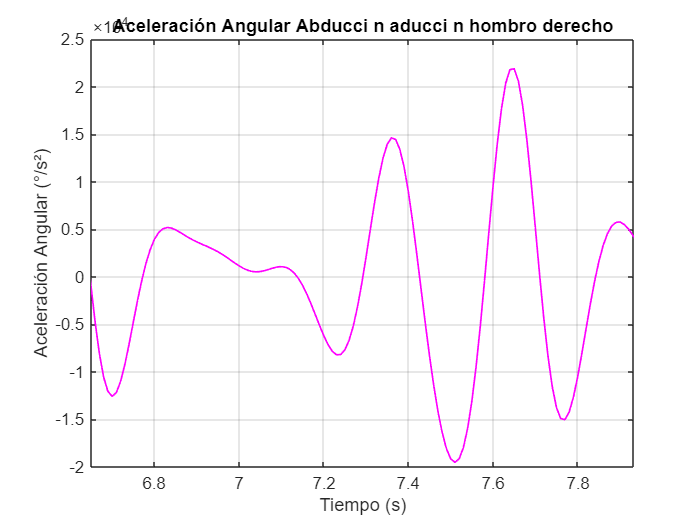

Aceleración Angular [Abducci_n_aducci_n_hombro_derecho]: Máximo: 21863.22°/s², Mínimo: -19509.06°/s²


    procesar_isen(Tiempo, Abducci_n_aducci_n_hombro_derecho_X, Abducci_n_aducci_n_hombro_derecho_Y, ti_f, tf_f);

    comparar_kinovea_isen(anguloAbduccionAduccionHombro_filtrado, tiempo_abad, Abducci_n_aducci_n_hombro_derecho_angulo, tiempo_Abducci_n_aducci_n_hombro_derecho, ti_f, tf_f);

📊 Resultados de Kinovea (anguloAbduccionAduccionHombro_filtrado - todo el rango):
   Media: 48.98°
   STD: 2.33°
   Máx: 53.73°
   Mín: 44.82°
   Rango: 8.91°

📊 Resultados de iSen (anguloAbduccionAduccionHombro_filtrado - intervalo [6.65, 7.93] s):
   Media: -4.64°
   STD: 32.15°
   Máx: 73.42°
   Mín: -52.64°
   Rango: 126.07°



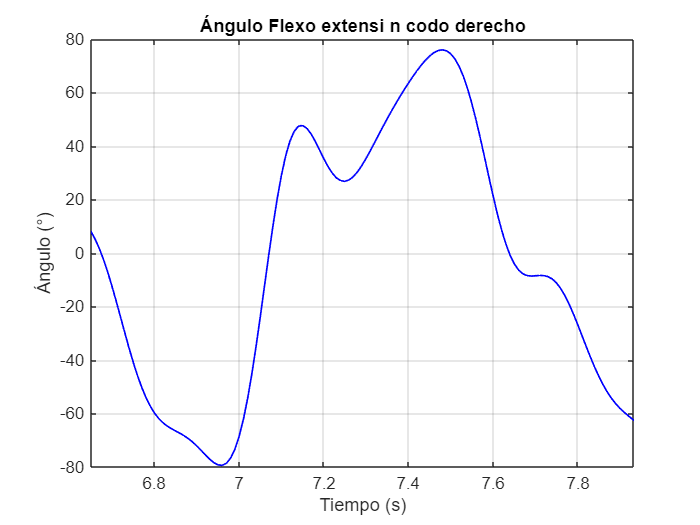

Ángulo [Flexo_extensi_n_codo_derecho]: Máximo: 201.67°, Mínimo: -220.57°


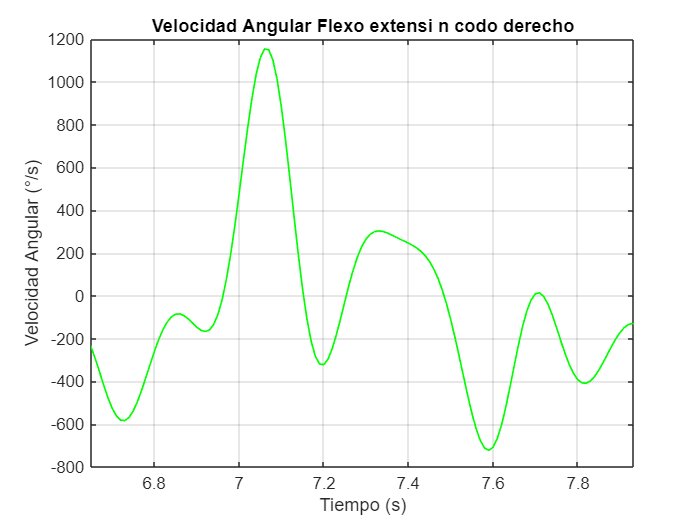

Velocidad Angular [Flexo_extensi_n_codo_derecho]: Máximo: 3841.46°/s, Mínimo: -3850.19°/s


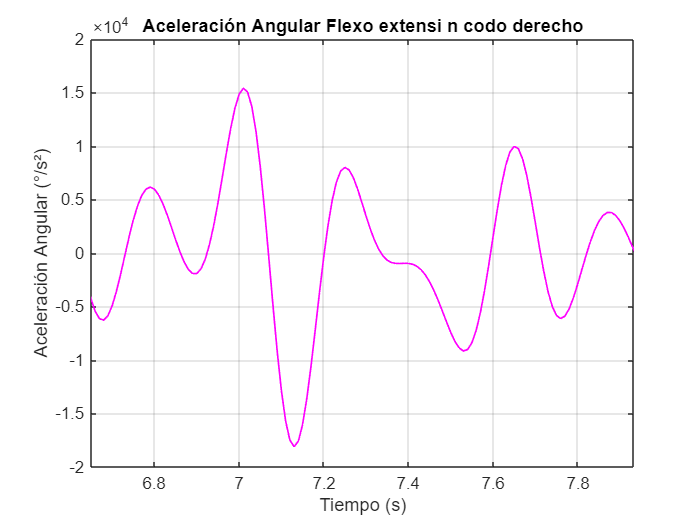

Aceleración Angular [Flexo_extensi_n_codo_derecho]: Máximo: 69246.93°/s², Mínimo: -53433.43°/s²


    procesar_isen(Tiempo, Flexo_extensi_n_codo_derecho_X, Flexo_extensi_n_codo_derecho_Y, ti_s, tf_s);

    comparar_kinovea_isen(anguloFlexionExtensionCodo_filtrado, tiempo_fck, Flexo_extensi_n_codo_derecho_angulo, tiempo_Flexo_extensi_n_codo_derecho, ti_s, tf_s);

📊 Resultados de Kinovea (anguloFlexionExtensionCodo_filtrado - todo el rango):
   Media: 118.87°
   STD: 23.55°
   Máx: 153.03°
   Mín: 80.99°
   Rango: 72.05°

📊 Resultados de iSen (anguloFlexionExtensionCodo_filtrado - intervalo [6.65, 7.93] s):
   Media: -2.86°
   STD: 48.84°
   Máx: 75.96°
   Mín: -79.37°
   Rango: 155.33°



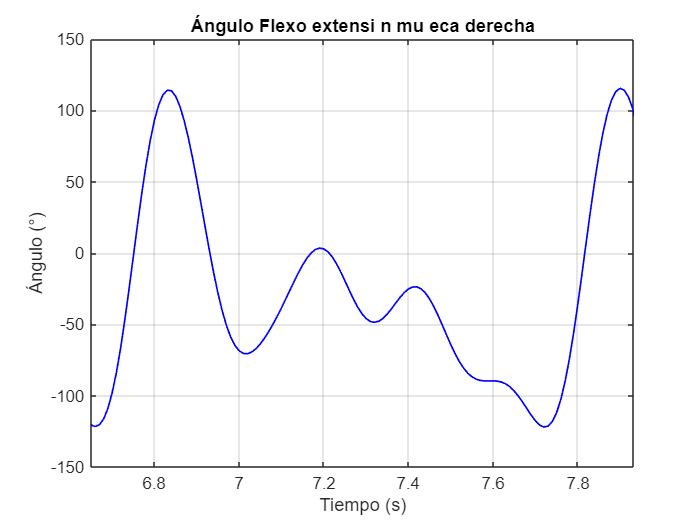

Ángulo [Flexo_extensi_n_mu_eca_derecha]: Máximo: 188.62°, Mínimo: -199.94°


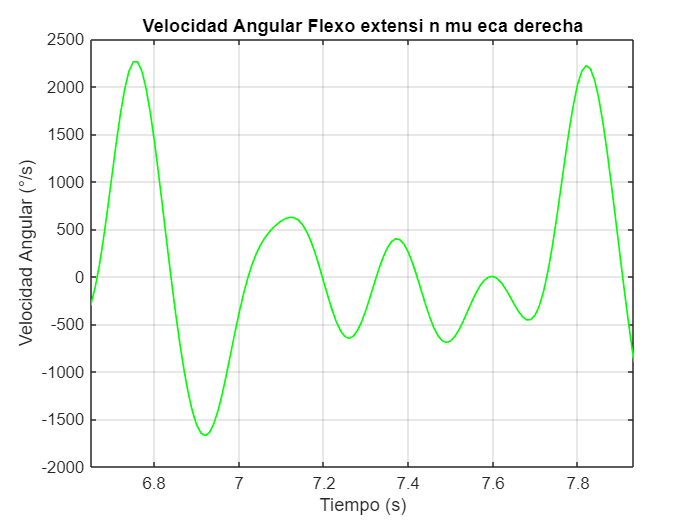

Velocidad Angular [Flexo_extensi_n_mu_eca_derecha]: Máximo: 3844.37°/s, Mínimo: -3641.75°/s


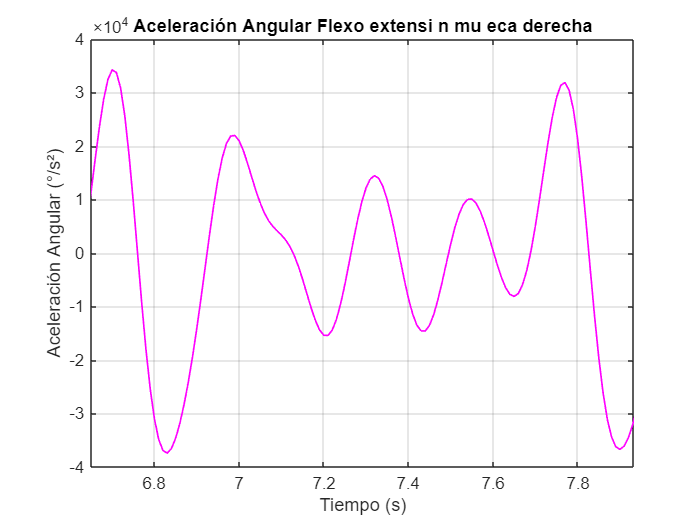

Aceleración Angular [Flexo_extensi_n_mu_eca_derecha]: Máximo: 83411.79°/s², Mínimo: -94661.87°/s²


    procesar_isen(Tiempo, Flexo_extensi_n_mu_eca_derecha_X,Flexo_extensi_n_mu_eca_derecha_Y, ti_f, tf_f);

    comparar_kinovea_isen(anguloFlexionExtensionMuneca_filtrado, tiempo_fenk, Flexo_extensi_n_mu_eca_derecha_angulo, tiempo_Flexo_extensi_n_mu_eca_derecha, ti_f, tf_f);

📊 Resultados de Kinovea (anguloFlexionExtensionMuneca_filtrado - todo el rango):
   Media: 155.35°
   STD: 3.70°
   Máx: 162.32°
   Mín: 145.74°
   Rango: 16.58°

📊 Resultados de iSen (anguloFlexionExtensionMuneca_filtrado - intervalo [6.65, 7.93] s):
   Media: -26.78°
   STD: 67.59°
   Máx: 115.44°
   Mín: -121.97°
   Rango: 237.42°



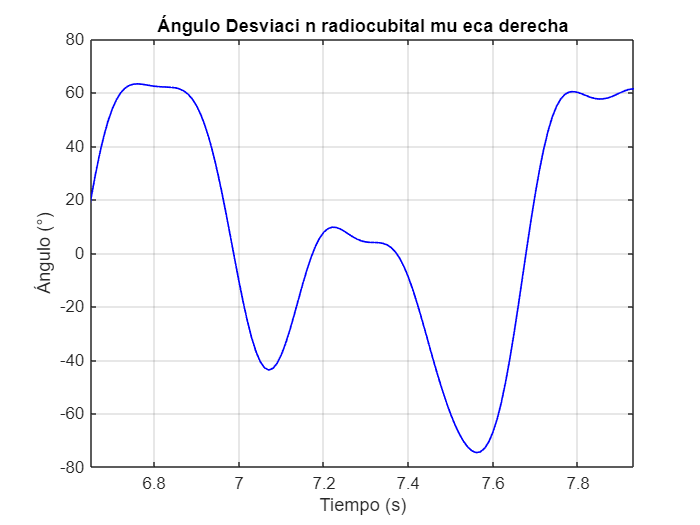

Ángulo [Desviaci_n_radiocubital_mu_eca_derecha]: Máximo: 83.39°, Mínimo: -81.98°


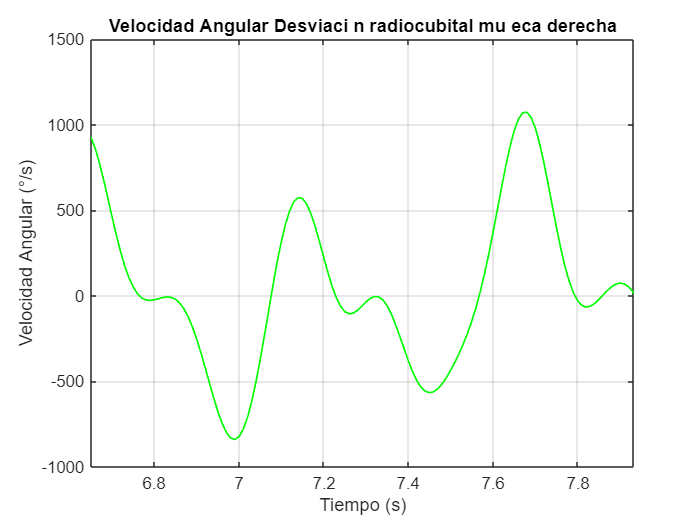

Velocidad Angular [Desviaci_n_radiocubital_mu_eca_derecha]: Máximo: 1364.95°/s, Mínimo: -1160.81°/s


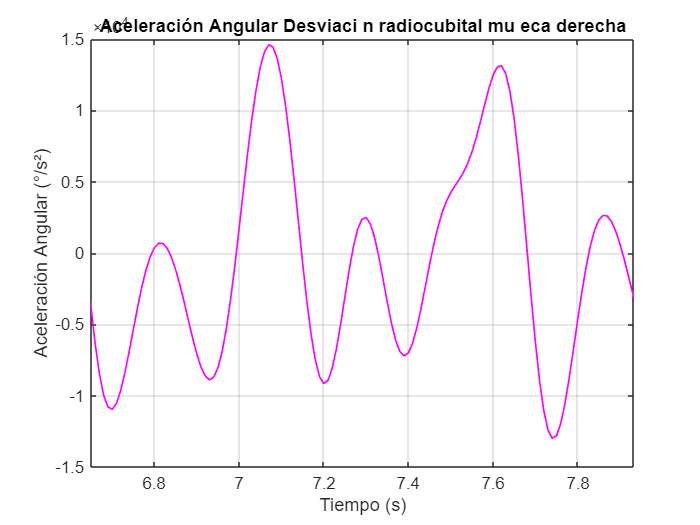

Aceleración Angular [Desviaci_n_radiocubital_mu_eca_derecha]: Máximo: 22585.76°/s², Mínimo: -23622.46°/s²


    procesar_isen(Tiempo, Desviaci_n_radiocubital_mu_eca_derecha_X,Desviaci_n_radiocubital_mu_eca_derecha_Y, ti_s, tf_s);

    comparar_kinovea_isen(desviacionRadiocubital_filtrado, tiempo_dk, Desviaci_n_radiocubital_mu_eca_derecha_angulo, tiempo_Desviaci_n_radiocubital_mu_eca_derecha, ti_s, tf_s);

📊 Resultados de Kinovea (desviacionRadiocubital_filtrado - todo el rango):
   Media: 12.15°
   STD: 7.14°
   Máx: 30.00°
   Mín: -0.12°
   Rango: 30.11°

📊 Resultados de iSen (desviacionRadiocubital_filtrado - intervalo [6.65, 7.93] s):
   Media: 9.87°
   STD: 44.36°
   Máx: 63.22°
   Mín: -74.61°
   Rango: 137.83°



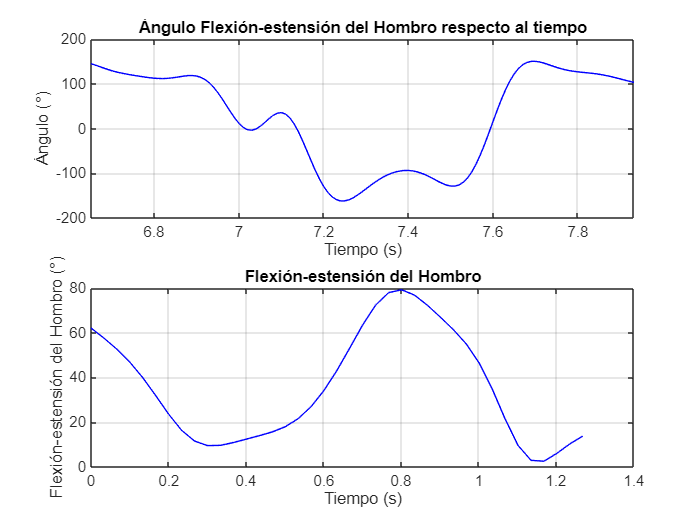

    desviacionFiltrada = anguloFlexionExtensionHombro_filtrado; % angulo de kinovea
    angulo_rad = Flexo_extensi_n_hombro_derecho_angulo; % angulo de isen
    tiempo_rad=tiempo_Flexo_extensi_n_hombro_derecho; % tiempo de isen
    tiempo_krad= tiempo_fexh; % tiempo de kinovea
    
    figure;
    subplot(2,1,1)
    plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
    title('Ángulo Flexión-estensión del Hombro respecto al tiempo');
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    grid on;
    xlim([ti_s tf_s])
    % Graficar la desviación radiocubital original y filtrada
    subplot(2,1,2)
    plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
    %plot(tiempo(idxMax), desviacionRadiocubital(idxMax), 'ro', 'MarkerSize', 8, 'DisplayName', 'Máxima Distancia');
    %plot(tiempo(idxMin), desviacionRadiocubital(idxMin), 'bo', 'MarkerSize', 8, 'DisplayName', 'Mínima Distancia');
    title('Flexión-estensión del Hombro');  % % con el nombre del angulo isen sin el "_Y" o el "_X"
    xlabel('Tiempo (s)');
    ylabel('Flexión-estensión del Hombro (°)'); % % con el nombre del anngulo de kinovea
    grid on;
    hold off;

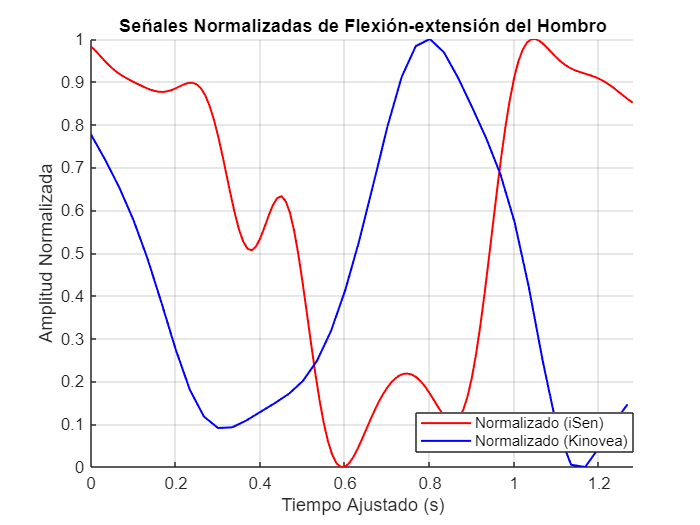

    % Crear un índice que filtra el rango de tiempo para la señal de iSen
    indices_rad = (tiempo_rad >= ti_s) & (tiempo_rad <= tf_s);
    tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo
    angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo
    
    % Ajustar el tiempo para que comience desde 0
    tiempo_rad_f = tiempo_rad_f - ti_s;
    
    % Normalizar las señales dentro del intervalo ti-tf
    norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
    norm_desv_krad = (desviacionFiltrada - min(desviacionFiltrada)) / (max(desviacionFiltrada) - min(desviacionFiltrada));
    
    % Ajustar el tiempo de Kinovea para que también comience desde 0
    tiempo_krad_adj = tiempo_krad - tiempo_krad(1);
    
    % Graficar las señales normalizadas
    figure;
    hold on;
    plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
    plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
    title('Señales Normalizadas de Flexión-extensión del Hombro');
    xlabel('Tiempo Ajustado (s)');
    ylabel('Amplitud Normalizada');
    legend('show', 'Location', 'best');
    xlim([0 tf_s - ti_s])
    grid on;
    hold off;
    legend(["Normalizado (iSen)", "Normalizado (Kinovea)"], "Position", [0.5943 0.1384 0.3107, 0.0774])

    
    media_kinovea = mean(norm_desv_krad);
    std_kinovea = std(norm_desv_krad);
    max_kinovea = max(norm_desv_krad);
    min_kinovea = min(norm_desv_krad);
    rango_kinovea = max_kinovea - min_kinovea;
    
    media_isen = mean(norm_ang_rad);
    std_isen = std(norm_ang_rad);
    max_isen = max(norm_ang_rad);
    min_isen = min(norm_ang_rad);
    rango_isen = max_isen - min_isen;
    
    % Mostrar resultados
    fprintf('Kinovea: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);

Kinovea: Media = 0.43, STD = 0.32, Máx = 1.00, Mín = 0.00, Rango = 1.00


    fprintf('iSen: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_isen, std_isen, max_isen, min_isen, rango_isen);

iSen: Media = 0.60, STD = 0.34, Máx = 1.00, Mín = 0.00, Rango = 1.00


    %variables que se van a recibir:
    desviacionFiltrada = anguloAbduccionAduccionHombro_filtrado; % angulo de kinovea
    angulo_rad = Abducci_n_aducci_n_hombro_derecho_angulo; % angulo de isen
    tiempo_rad=tiempo_Abducci_n_aducci_n_hombro_derecho; % tiempo de isen
    tiempo_krad= tiempo_abad; % tiempo de kinovea
    ti_f

ti_f = 6.6500

     tf_f

tf_f = 7.9332

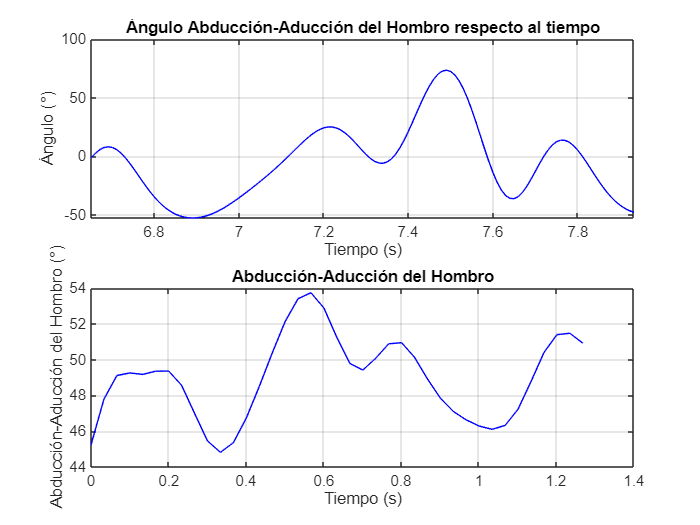

    
    figure;
    subplot(2,1,1)
    plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
    title('Ángulo Abducción-Aducción del Hombro respecto al tiempo');
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    grid on;
    xlim([ti_f tf_f])
    subplot(2,1,2)
    plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
    title('Abducción-Aducción del Hombro');
    xlabel('Tiempo (s)');
    ylabel('Abducción-Aducción del Hombro (°)');
    grid on;
    hold off;

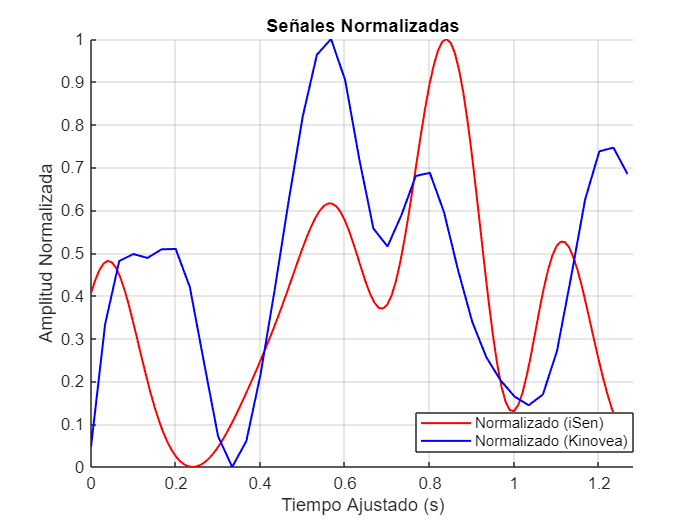

    % Crear un índice que filtra el rango de tiempo para la señal de iSen
    indices_rad = (tiempo_rad >= ti_f) & (tiempo_rad <= tf_f);
    tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo
    angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo
    
    % Ajustar el tiempo para que comience desde 0
    tiempo_rad_f = tiempo_rad_f - ti_f;
    
    % Normalizar las señales dentro del intervalo ti-tf
    norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
    norm_desv_krad = (desviacionFiltrada - min(desviacionFiltrada)) / (max(desviacionFiltrada) - min(desviacionFiltrada));
    
    % Ajustar el tiempo de Kinovea para que también comience desde 0
    tiempo_krad_adj = tiempo_krad - tiempo_krad(1);
    
    % Graficar las señales normalizadas
    figure;
    hold on;
    plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
    plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
    title('Señales Normalizadas') %nombre de el angulo de kinovea sin el _X o el _Y
    xlabel('Tiempo Ajustado (s)');
    ylabel('Amplitud Normalizada');
    legend('show', 'Location', 'best');
    xlim([0 tf_f - ti_f])
    grid on;
    hold off;
    legend(["Normalizado (iSen)", "Normalizado (Kinovea)"], "Position", [0.5943 0.1384 0.3107, 0.0774])

    media_kinovea = mean(norm_desv_krad);
    std_kinovea = std(norm_desv_krad);
    max_kinovea = max(norm_desv_krad);
    min_kinovea = min(norm_desv_krad);
    rango_kinovea = max_kinovea - min_kinovea;
    media_isen = mean(norm_ang_rad);
    std_isen = std(norm_ang_rad);
    max_isen = max(norm_ang_rad);
    min_isen = min(norm_ang_rad);
    rango_isen = max_isen - min_isen;
    
    % Mostrar resultados
    fprintf('Kinovea: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);

Kinovea: Media = 0.47, STD = 0.26, Máx = 1.00, Mín = 0.00, Rango = 1.00


    fprintf('iSen: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_isen, std_isen, max_isen, min_isen, rango_isen);

iSen: Media = 0.38, STD = 0.26, Máx = 1.00, Mín = 0.00, Rango = 1.00


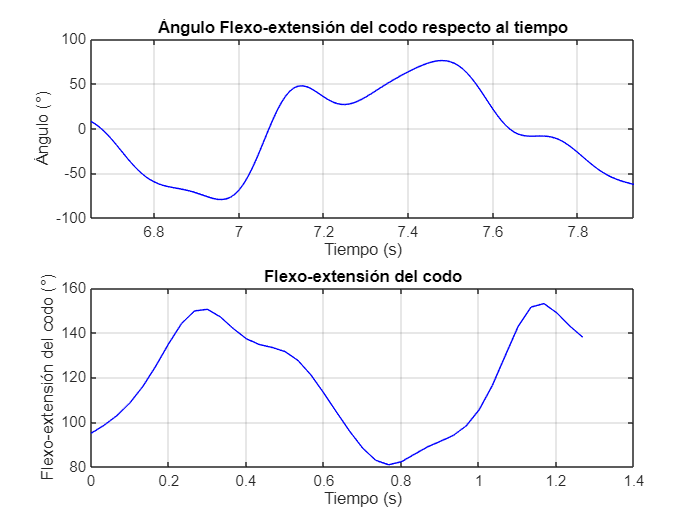

    desviacionFiltrada = anguloFlexionExtensionCodo_filtrado; 
    angulo_rad =Flexo_extensi_n_codo_derecho_angulo;
    tiempo_rad=tiempo_Flexo_extensi_n_codo_derecho;
    tiempo_krad=tiempo_fck;
    
    
    figure;
    subplot(2,1,1)
    plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
    title('Ángulo Flexo-extensión del codo respecto al tiempo');
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    grid on;
    xlim([ti_s tf_s])
    % Graficar la desviación radiocubital original y filtrada
    subplot(2,1,2)
    plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
    %plot(tiempo(idxMax), desviacionRadiocubital(idxMax), 'ro', 'MarkerSize', 8, 'DisplayName', 'Máxima Distancia');
    %plot(tiempo(idxMin), desviacionRadiocubital(idxMin), 'bo', 'MarkerSize', 8, 'DisplayName', 'Mínima Distancia');
    title('Flexo-extensión del codo');
    xlabel('Tiempo (s)');
    ylabel('Flexo-extensión del codo (°)');
    grid on;
    hold off;

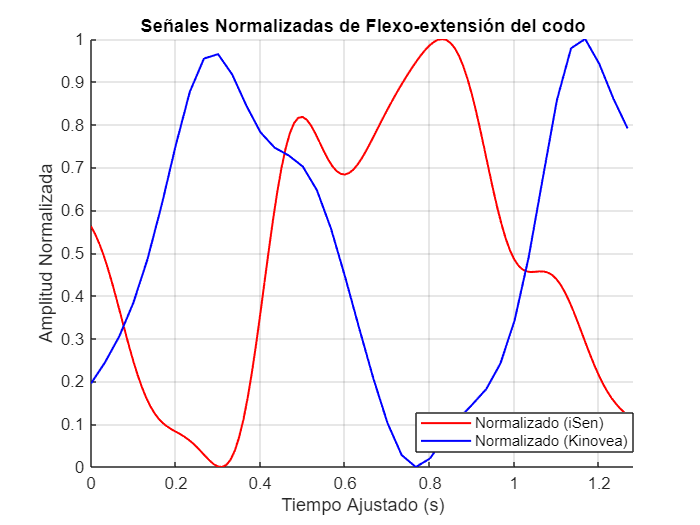

    % Crear un índice que filtra el rango de tiempo para la señal de iSen
    indices_rad = (tiempo_rad >= ti_s) & (tiempo_rad <= tf_s);
    tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo
    angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo
    
    % Ajustar el tiempo para que comience desde 0
    tiempo_rad_f = tiempo_rad_f - ti_s;
    
    % Normalizar las señales dentro del intervalo ti-tf
    norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
    norm_desv_krad = (desviacionFiltrada - min(desviacionFiltrada)) / (max(desviacionFiltrada) - min(desviacionFiltrada));
    
    % Ajustar el tiempo de Kinovea para que también comience desde 0
    tiempo_krad_adj = tiempo_krad - tiempo_krad(1);
    
    % Graficar las señales normalizadas
    figure;
    hold on;
    plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
    plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
    title('Señales Normalizadas de Flexo-extensión del codo');
    xlabel('Tiempo Ajustado (s)');
    ylabel('Amplitud Normalizada');
    legend('show', 'Location', 'best');
    xlim([0 tf_s - ti_s])
    grid on;
    hold off;
    legend(["Normalizado (iSen)", "Normalizado (Kinovea)"], "Position", [0.5943 0.1384 0.3107, 0.0774])

    
    media_kinovea = mean(norm_desv_krad);
    std_kinovea = std(norm_desv_krad);
    max_kinovea = max(norm_desv_krad);
    min_kinovea = min(norm_desv_krad);
    rango_kinovea = max_kinovea - min_kinovea;
    
    media_isen = mean(norm_ang_rad);
    std_isen = std(norm_ang_rad);
    max_isen = max(norm_ang_rad);
    min_isen = min(norm_ang_rad);
    rango_isen = max_isen - min_isen;
    
    % Mostrar resultados
    fprintf('Kinovea: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);

Kinovea: Media = 0.53, STD = 0.33, Máx = 1.00, Mín = 0.00, Rango = 1.00


    fprintf('iSen: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_isen, std_isen, max_isen, min_isen, rango_isen);

iSen: Media = 0.49, STD = 0.31, Máx = 1.00, Mín = 0.00, Rango = 1.00


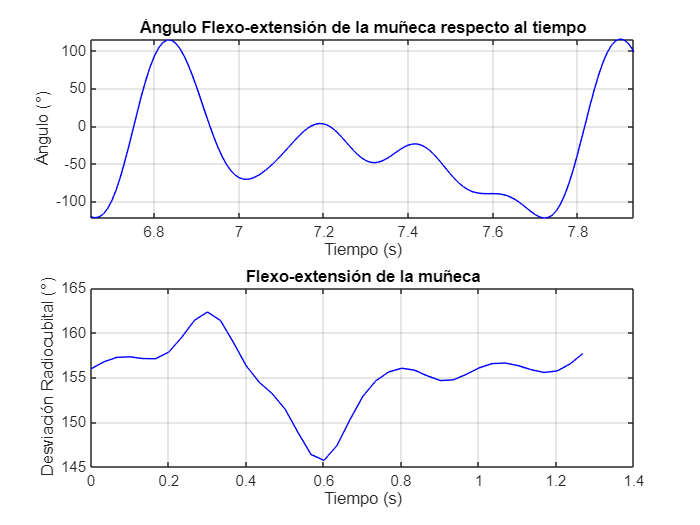

    desviacionFiltrada = anguloFlexionExtensionMuneca_filtrado; 
    angulo_rad = Flexo_extensi_n_mu_eca_derecha_angulo;
    tiempo_rad=tiempo_Flexo_extensi_n_mu_eca_derecha;
    tiempo_krad=tiempo_fenk;
    % ti=6.083;
    % tf=ti+times
    
    figure;
    subplot(2,1,1)
    plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
    title('Ángulo Flexo-extensión de la muñeca respecto al tiempo');
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    grid on;
    xlim([ti_f tf_f])
    % Graficar la desviación radiocubital original y filtrada
    subplot(2,1,2)
    plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
    %plot(tiempo(idxMax), desviacionRadiocubital(idxMax), 'ro', 'MarkerSize', 8, 'DisplayName', 'Máxima Distancia');
    %plot(tiempo(idxMin), desviacionRadiocubital(idxMin), 'bo', 'MarkerSize', 8, 'DisplayName', 'Mínima Distancia');
    title('Flexo-extensión de la muñeca');
    xlabel('Tiempo (s)');
    ylabel('Desviación Radiocubital (°)');
    grid on;
    hold off;

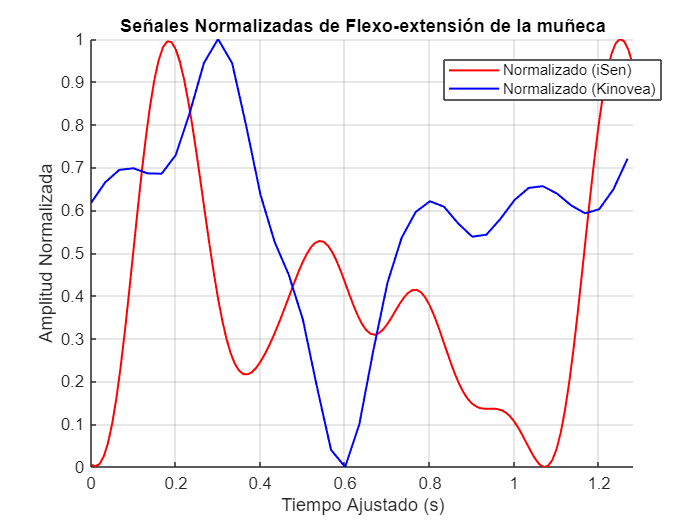

    % Crear un índice que filtra el rango de tiempo para la señal de iSen
    indices_rad = (tiempo_rad >= ti_f) & (tiempo_rad <= tf_f);
    tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo
    angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo
    
    % Ajustar el tiempo para que comience desde 0
    tiempo_rad_f = tiempo_rad_f - ti_f;
    
    % Normalizar las señales dentro del intervalo ti-tf
    norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
    norm_desv_krad = (desviacionFiltrada - min(desviacionFiltrada)) / (max(desviacionFiltrada) - min(desviacionFiltrada));
    
    % Ajustar el tiempo de Kinovea para que también comience desde 0
    tiempo_krad_adj = tiempo_krad - tiempo_krad(1);
    
    % Graficar las señales normalizadas
    figure;
    hold on;
    plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
    plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
    title('Señales Normalizadas de Flexo-extensión de la muñeca');
    xlabel('Tiempo Ajustado (s)');
    ylabel('Amplitud Normalizada');
    legend('show', 'Location', 'best');
    xlim([0 tf_f - ti_f])
    grid on;
    hold off;
    legend(["Normalizado (iSen)", "Normalizado (Kinovea)"], "Position", [0.6346 0.8103 0.3107, 0.0774])

    
    media_kinovea = mean(norm_desv_krad);
    std_kinovea = std(norm_desv_krad);
    max_kinovea = max(norm_desv_krad);
    min_kinovea = min(norm_desv_krad);
    rango_kinovea = max_kinovea - min_kinovea;
    
    media_isen = mean(norm_ang_rad);
    std_isen = std(norm_ang_rad);
    max_isen = max(norm_ang_rad);
    min_isen = min(norm_ang_rad);
    rango_isen = max_isen - min_isen;
    
    % Mostrar resultados
    fprintf('Kinovea: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);

Kinovea: Media = 0.58, STD = 0.22, Máx = 1.00, Mín = 0.00, Rango = 1.00


    fprintf('iSen: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_isen, std_isen, max_isen, min_isen, rango_isen);

iSen: Media = 0.40, STD = 0.28, Máx = 1.00, Mín = 0.00, Rango = 1.00


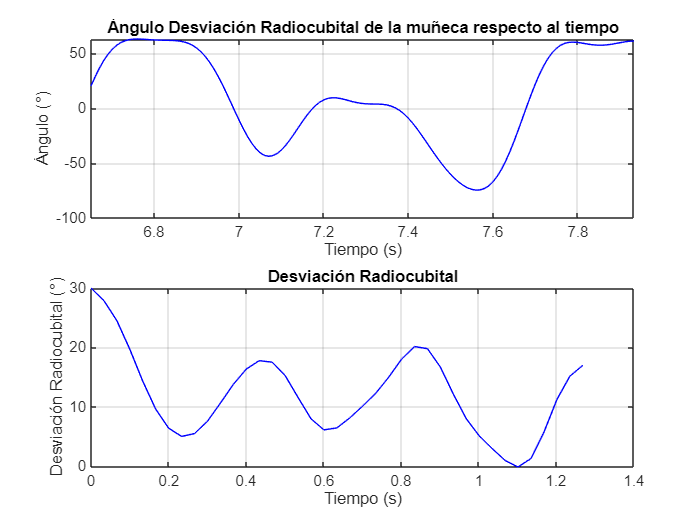

    desviacionFiltrada = desviacionRadiocubital_filtrado; 
    angulo_rad =Desviaci_n_radiocubital_mu_eca_derecha_angulo;
    tiempo_rad=tiempo_Desviaci_n_radiocubital_mu_eca_derecha;
    tiempo_krad=tiempo_dk;
    
    figure;
    subplot(2,1,1)
    plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
    title('Ángulo Desviación Radiocubital de la muñeca respecto al tiempo');
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    grid on;
    xlim([ti_s tf_s])
    % Graficar la desviación radiocubital original y filtrada
    subplot(2,1,2)
    plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
    %plot(tiempo(idxMax), desviacionRadiocubital(idxMax), 'ro', 'MarkerSize', 8, 'DisplayName', 'Máxima Distancia');
    %plot(tiempo(idxMin), desviacionRadiocubital(idxMin), 'bo', 'MarkerSize', 8, 'DisplayName', 'Mínima Distancia');
    title('Desviación Radiocubital');
    xlabel('Tiempo (s)');
    ylabel('Desviación Radiocubital (°)');
    grid on;
    hold off;

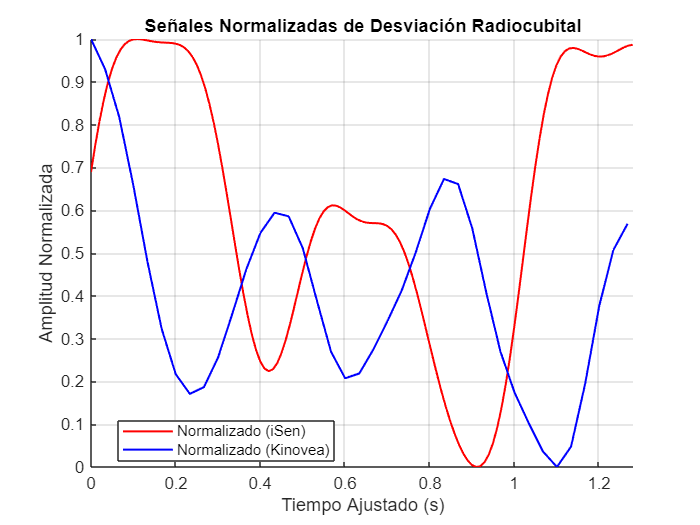

    % Crear un índice que filtra el rango de tiempo para la señal de iSen
    indices_rad = (tiempo_rad >= ti_s) & (tiempo_rad <= tf_s);
    tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo
    angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo
    
    % Ajustar el tiempo para que comience desde 0
    tiempo_rad_f = tiempo_rad_f - ti_s;
    
    % Normalizar las señales dentro del intervalo ti-tf
    norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
    norm_desv_krad = (desviacionFiltrada - min(desviacionFiltrada)) / (max(desviacionFiltrada) - min(desviacionFiltrada));
    
    % Ajustar el tiempo de Kinovea para que también comience desde 0
    tiempo_krad_adj = tiempo_krad - tiempo_krad(1);
    
    % Graficar las señales normalizadas
    figure;
    hold on;
    plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
    plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
    title('Señales Normalizadas de Desviación Radiocubital');
    xlabel('Tiempo Ajustado (s)');
    ylabel('Amplitud Normalizada');
    legend('show', 'Location', 'best');
    xlim([0 tf_s - ti_s])
    grid on;
    hold off;

    media_kinovea = mean(norm_desv_krad);
    std_kinovea = std(norm_desv_krad);
    max_kinovea = max(norm_desv_krad);
    min_kinovea = min(norm_desv_krad);
    rango_kinovea = max_kinovea - min_kinovea;
    
    media_isen = mean(norm_ang_rad);
    std_isen = std(norm_ang_rad);
    max_isen = max(norm_ang_rad);
    min_isen = min(norm_ang_rad);
    rango_isen = max_isen - min_isen;
    
    % Mostrar resultados
    fprintf('Kinovea: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);

Kinovea: Media = 0.41, STD = 0.24, Máx = 1.00, Mín = 0.00, Rango = 1.00


    fprintf('iSen: Media = %.2f, STD = %.2f, Máx = %.2f, Mín = %.2f, Rango = %.2f\n', ...
        media_isen, std_isen, max_isen, min_isen, rango_isen);

iSen: Media = 0.61, STD = 0.32, Máx = 1.00, Mín = 0.00, Rango = 1.00


% Archivo Excel de salida
excelFileName = 'resultados_cinematica_completo.xlsx';

% Inicializar resultados
resultados = {};

%% Función auxiliar para estadísticas rápidas
calc_stats = @(x) [mean(x), std(x), max(x), min(x), max(x)-min(x)];

%% 📌 Ángulo Abducción-Aducción Hombro
resultados(1,1) = {'Abducción-Aducción Hombro'};
resultados(2:6,1) = {'Media'; 'STD'; 'Máx'; 'Mín'; 'Rango'};
resultados(1,[2 3 4]) = {'Ángulo','Velocidad','Aceleración'};

resultados(2:6,2) = num2cell(calc_stats(anguloAbduccionAduccionHombro_filtrado));
resultados(2:6,3) = num2cell(calc_stats(anguloAbduccionAduccionHombro_velocidad));
resultados(2:6,4) = num2cell(calc_stats(anguloAbduccionAduccionHombro_aceleracion));

%% 📌 Ángulo Flexión-Extensión Hombro
resultados(8,1) = {'Flexión-Extensión Hombro'};
resultados(9:13,1) = {'Media'; 'STD'; 'Máx'; 'Mín'; 'Rango'};
resultados(8,[2 3 4]) = {'Ángulo','Velocidad','Aceleración'};

resultados(9:13,2) = num2cell(calc_stats(anguloFlexionExtensionHombro_filtrado));
resultados(9:13,3) = num2cell(calc_stats(anguloFlexionExtensionHombro_velocidad));
resultados(9:13,4) = num2cell(calc_stats(anguloFlexionExtensionHombro_aceleracion));

%% 📌 Ángulo Flexión-Extensión Codo
resultados(15,1) = {'Flexión-Extensión Codo'};
resultados(16:20,1) = {'Media'; 'STD'; 'Máx'; 'Mín'; 'Rango'};
resultados(15,[2 3 4]) = {'Ángulo','Velocidad','Aceleración'};

resultados(16:20,2) = num2cell(calc_stats(anguloFlexionExtensionCodo_filtrado));
resultados(16:20,3) = num2cell(calc_stats(anguloFlexionExtensionCodo_velocidad));
resultados(16:20,4) = num2cell(calc_stats(anguloFlexionExtensionCodo_aceleracion));

%% 📌 Ángulo Flexión-Extensión Muñeca
resultados(22,1) = {'Flexión-Extensión Muñeca'};
resultados(23:27,1) = {'Media'; 'STD'; 'Máx'; 'Mín'; 'Rango'};
resultados(22,[2 3 4]) = {'Ángulo','Velocidad','Aceleración'};

resultados(23:27,2) = num2cell(calc_stats(anguloFlexionExtensionMuneca_filtrado));
resultados(23:27,3) = num2cell(calc_stats(anguloFlexionExtensionMuneca_velocidad));
resultados(23:27,4) = num2cell(calc_stats(anguloFlexionExtensionMuneca_aceleracion));

%% 📌 Desviación Radiocubital Muñeca
resultados(29,1) = {'Desviación Radiocubital Muñeca'};
resultados(30:34,1) = {'Media'; 'STD'; 'Máx'; 'Mín'; 'Rango'};
resultados(29,[2 3 4]) = {'Ángulo','Velocidad','Aceleración'};

resultados(30:34,2) = num2cell(calc_stats(desviacionRadiocubital_filtrado));
resultados(30:34,3) = num2cell(calc_stats(desviacionRadiocubital_velocidad));
resultados(30:34,4) = num2cell(calc_stats(desviacionRadiocubital_aceleracion));

%% 📗 Exportar al Excel
xlswrite(excelFileName, resultados);
disp(['✅ Resultados guardados en: ', excelFileName]);

✅ Resultados guardados en: resultados_cinematica_completo.xlsx


% === Exportar todas las variables cinemáticas con sus respectivos tiempos ===
% Guardará: Tiempo, Ángulo, Velocidad, Aceleración por cada una de las 5 variables

% Archivo de salida
archivoExcel = 'datos_cinematica.xlsx';

% Definición explícita de las variables
data = {
    'anguloAbduccionAduccionHombro_filtrado',   'tiempo_abad',  'anguloAbduccionAduccionHombro_velocidad',   'anguloAbduccionAduccionHombro_aceleracion';
    'anguloFlexionExtensionHombro_filtrado',    'tiempo_fexh',  'anguloFlexionExtensionHombro_velocidad',    'anguloFlexionExtensionHombro_aceleracion';
    'anguloFlexionExtensionCodo_filtrado',      'tiempo_fck',   'anguloFlexionExtensionCodo_velocidad',      'anguloFlexionExtensionCodo_aceleracion';
    'anguloFlexionExtensionMuneca_filtrado',    'tiempo_fenk',  'anguloFlexionExtensionMuneca_velocidad',    'anguloFlexionExtensionMuneca_aceleracion';
    'desviacionRadiocubital_filtrado',          'tiempo_dk',    'desviacionRadiocubital_velocidad',          'desviacionRadiocubital_aceleracion';
};

% Inicializar tabla combinada
tablaFinal = table();

for i = 1:size(data, 1)
    % Extraer nombres de variables
    anguloVar = data{i, 1};
    tiempoVar = data{i, 2};
    velVar    = data{i, 3};
    accVar    = data{i, 4};

    % Evaluar datos desde el workspace
    angulo = eval(anguloVar);
    tiempo = eval(tiempoVar);
    velocidad = eval(velVar);
    aceleracion = eval(accVar);

    % Igualar tamaños (usar mínimo en caso de desfase)
    N = min([length(tiempo), length(angulo), length(velocidad), length(aceleracion)]);
    tiempo = tiempo(1:N);
    angulo = angulo(1:N);
    velocidad = velocidad(1:N);
    aceleracion = aceleracion(1:N);

    % Crear tabla parcial
    subTabla = table(tiempo(:), angulo(:), velocidad(:), aceleracion(:), ...
        'VariableNames', {
            ['Tiempo_' anguloVar], ...
            ['Angulo_' anguloVar], ...
            ['Velocidad_' anguloVar], ...
            ['Aceleracion_' anguloVar] ...
        });

    % Unir con la tabla final
    tablaFinal = [tablaFinal subTabla];
end

% Exportar al Excel
writetable(tablaFinal, archivoExcel);
disp(['✅ Excel guardado: ' archivoExcel]);

✅ Excel guardado: datos_cinematica.xlsx


%primero sagital y luego frontal
%primer propulsión y luego recuperación
tiempos = [0.8, 1.3, 0.3, 0.8, 0.8, 1.3, 0.3, 0.8];
procesarISENporFase(tiempos,ti_s,ti_f);

✅ Archivo "resultados_percentiles.xlsx" generado por hojas.


    function [velocidadAngular, aceleracionAngular, anguloFiltrado] = procesarAngulo(anguloOriginal, tiempo, nombreOriginal)
        % ==============================
        % Aplicar Filtro Pasa-Baja Butterworth
        % ==============================
        fs = 29.97; % Frecuencia de muestreo estimada
        fc = 6;   % Frecuencia de corte en Hz
        orden = 4; % Orden del filtro
        [b, a] = butter(orden, fc/(fs/2), 'low'); % Diseñar filtro
        anguloFiltrado = filtfilt(b, a, anguloOriginal); % Aplicar filtro
    
        % ==============================
        % Cálculo de Velocidad y Aceleración Angular
        % ==============================
        dt = diff(tiempo); % Diferencia de tiempo entre frames
        velocidadAngular = diff(anguloFiltrado) ./ dt; % Velocidad angular (derivada primera)
        aceleracionAngular = diff(velocidadAngular) ./ dt(2:end); % Aceleración angular (derivada segunda)
    
        % ==============================
        % Encontrar valores máximos y mínimos con sus tiempos
        % ==============================
    
        % Ángulo
        [maxAng, idxMaxAng] = max(anguloFiltrado);
        [minAng, idxMinAng] = min(anguloFiltrado);
        tiempoMaxAng = tiempo(idxMaxAng);
        tiempoMinAng = tiempo(idxMinAng);
    
        % Velocidad Angular
        [maxVel, idxMaxVel] = max(velocidadAngular);
        [minVel, idxMinVel] = min(velocidadAngular);
        tiempoMaxVel = tiempo(idxMaxVel+1); % Ajuste porque velocidad es diff(ángulo)
        tiempoMinVel = tiempo(idxMinVel+1);
    
        % Aceleración Angular
        [maxAcc, idxMaxAcc] = max(aceleracionAngular);
        [minAcc, idxMinAcc] = min(aceleracionAngular);
        tiempoMaxAcc = tiempo(idxMaxAcc+2); % Ajuste porque aceleración es diff(velocidad)
        tiempoMinAcc = tiempo(idxMinAcc+2);
    
        % ==============================
        % Mostrar valores máximos y mínimos con todos los decimales
        % ==============================
        fprintf('%s - Ángulo:\n', nombreOriginal);
        fprintf('Máximo: %.6f° en t = %.10f s\n', maxAng, tiempoMaxAng);
        fprintf('Mínimo: %.6f° en t = %.10f s\n\n', minAng, tiempoMinAng);
    
        fprintf('%s - Velocidad Angular:\n', nombreOriginal);
        fprintf('Máximo: %.6f°/s en t = %.10f s\n', maxVel, tiempoMaxVel);
        fprintf('Mínimo: %.6f°/s en t = %.10f s\n\n', minVel, tiempoMinVel);
    
        fprintf('%s - Aceleración Angular:\n', nombreOriginal);
        fprintf('Máximo: %.6f°/s² en t = %.10f s\n', maxAcc, tiempoMaxAcc);
        fprintf('Mínimo: %.6f°/s² en t = %.10f s\n\n', minAcc, tiempoMinAcc);
    
        % ==============================
        % Animación en los tiempos clave (Máximos y Mínimos)
        % ==============================
        tiempos_criticos = [tiempoMaxAng, tiempoMinAng, tiempoMaxVel, tiempoMinVel, tiempoMaxAcc, tiempoMinAcc];
        nombres_animaciones = {'Ángulo Máx', 'Ángulo Mín', 'Velocidad Máx', 'Velocidad Mín', 'Aceleración Máx', 'Aceleración Mín'};
    
        matrices_a_animar_frontral = {'est_fnt_normXY', 'hnd_fnt_normXY', 'cod_fnt_normXY', 'h_ant_fnt_normXY', ...
                                      'cod_med_fnt_normXY', 'rad_fnt_normXY', 'esc_fnt_normXY', 'h_post_fnt_normXY'};
        conexiones_frontral = [
            1, 7; 7, 8; 1, 4; 8, 4; 5, 4; 3, 8; 5, 3; 6, 5; 2, 3; 6, 2;
        ];
        
        matrices_a_animar_sagital = {'mnk_sag_fixed', 'cod_sag_fixed', 'h_ant_sag_fixed', 'rad_sag_fixed', 'cub_sag_fixed', ...
                                     'h_post_sag_fixed', 'esc_sag_fixed'};
        conexiones_sagital = [
            1, 4; 1, 5; 5, 4; 4, 2; 5, 2; 6, 3; 6, 7; 7, 3; 3, 2; 6, 2;
        ];
    
        for i = 1:length(tiempos_criticos)
            tiempo_objetivo = tiempos_criticos(i);
            nombre_animacion = nombres_animaciones{i};
    
            % Verificar si el tiempo objetivo está dentro del rango del tiempo disponible
            if tiempo_objetivo < min(tiempo) || tiempo_objetivo > max(tiempo)
                fprintf('⚠️ Tiempo %.6f s fuera del rango disponible. Se omite la animación.\n', tiempo_objetivo);
            continue; % Salta esta iteración si el tiempo no es válido
            end
    
            % Encontrar el índice del tiempo más cercano
            [~, idx_cercano] = min(abs(tiempo - tiempo_objetivo));
    
            % Verificar que el índice encontrado sea válido
            if idx_cercano < 1 || idx_cercano > length(tiempo)
                fprintf('⚠️ Índice no válido para t = %.6f s. Se omite la animación.\n', tiempo_objetivo);
            continue;
            end
    
            % Animación en el plano Frontal
            figure;
            subplot(1,2,1);
            animar_postura(idx_cercano, matrices_a_animar_frontral, conexiones_frontral);
            title(['Frontal - ', nombre_animacion, ' en t = ', num2str(tiempo_objetivo, '%.6f'), ' s']);
            
            % Animación en el plano Sagital
            subplot(1,2,2);
            animar_postura(idx_cercano, matrices_a_animar_sagital, conexiones_sagital);
            title(['Sagital - ', nombre_animacion, ' en t = ', num2str(tiempo_objetivo, '%.6f'), ' s']);
        end
    end
    
    function [velocidadAngular, aceleracionAngular, anguloFiltrado] = procesarAngulo2(anguloOriginal, tiempo, nombreOriginal)
        % ==============================
        % Aplicar Filtro Pasa-Baja Butterworth
        % ==============================
        fs = 29.97; % Frecuencia de muestreo estimada
        fc = 6;   % Frecuencia de corte en Hz
        orden = 4; % Orden del filtro
        [b, a] = butter(orden, fc/(fs/2), 'low'); % Diseñar filtro
        anguloFiltrado = filtfilt(b, a, anguloOriginal); % Aplicar filtro
    
        % ==============================
        % Cálculo de Velocidad y Aceleración Angular
        % ==============================
        dt = diff(tiempo); % Diferencia de tiempo entre frames
        velocidadAngular = diff(anguloFiltrado) ./ dt; % Velocidad angular (derivada primera)
        aceleracionAngular = diff(velocidadAngular) ./ dt(2:end); % Aceleración angular (derivada segunda)
    
        % ==============================
        % Encontrar valores máximos y mínimos con sus tiempos
        % ==============================
    
        % Ángulo
        [maxAng, idxMaxAng] = max(anguloFiltrado);
        [minAng, idxMinAng] = min(anguloFiltrado);
        tiempoMaxAng = tiempo(idxMaxAng);
        tiempoMinAng = tiempo(idxMinAng);
    
        % Velocidad Angular
        [maxVel, idxMaxVel] = max(velocidadAngular);
        [minVel, idxMinVel] = min(velocidadAngular);
        tiempoMaxVel = tiempo(idxMaxVel+1); % Ajuste porque velocidad es diff(ángulo)
        tiempoMinVel = tiempo(idxMinVel+1);
    
        % Aceleración Angular
        [maxAcc, idxMaxAcc] = max(aceleracionAngular);
        [minAcc, idxMinAcc] = min(aceleracionAngular);
        tiempoMaxAcc = tiempo(idxMaxAcc+2); % Ajuste porque aceleración es diff(velocidad)
        tiempoMinAcc = tiempo(idxMinAcc+2);
    
        % ==============================
        % Gráfico 1: Ángulo (Original y Filtrado)
        % ==============================
        figure;
        plot(tiempo, anguloOriginal, 'r', 'LineWidth', 1); hold on;
        plot(tiempo, anguloFiltrado, 'b', 'LineWidth', 1);
        title(['Ángulo de ', nombreOriginal]);
        xlabel('Tiempo (s)');
        ylabel('Ángulo (°)');
        legend('Original', 'Filtrado');
        grid on;
        hold off;
    
        % ==============================
        % Gráfico 2: Velocidad Angular
        % ==============================
        figure;
        plot(tiempo(2:end), velocidadAngular, 'g', 'LineWidth', 1.5);
        title(['Velocidad Angular de ', nombreOriginal]);
        xlabel('Tiempo (s)');
        ylabel('Velocidad Angular (°/s)');
        grid on;
    
        % ==============================
        % Gráfico 3: Aceleración Angular
        % ==============================
        figure;
        plot(tiempo(3:end), aceleracionAngular, 'm', 'LineWidth', 1.5);
        title(['Aceleración Angular de ', nombreOriginal]);
        xlabel('Tiempo (s)');
        ylabel('Aceleración Angular (°/s²)');
        grid on;
        % ==============================
        % Guardar los vectores con nombres personalizados
        % ==============================
        nombreFiltrado = [nombreOriginal, '_filtrado'];
        nombreVelocidad = [nombreOriginal, '_velocidad'];
        nombreAceleracion = [nombreOriginal, '_aceleracion'];
    
        assignin('base', nombreFiltrado, anguloFiltrado);
        assignin('base', nombreVelocidad, velocidadAngular);
        assignin('base', nombreAceleracion, aceleracionAngular);
    end
    
    
    function animar_postura(tiempo_objetivo, matrices_a_animar, conexiones)
        % Encuentra el índice de tiempo más cercano
        frame_rate = 29.97;
        frame_idx = round(tiempo_objetivo * frame_rate);
        
        % Definir colores para cada punto
        colores = lines(length(matrices_a_animar));
    
        hold on;
        xlabel('X (cm)');
        ylabel('Y (cm)');
        grid on;
        axis equal;
        
        puntos = gobjects(size(matrices_a_animar));
        lineas = gobjects(size(conexiones, 1), 1);
    
        for i = 1:length(matrices_a_animar)
            matriz = evalin('base', matrices_a_animar{i});
            if frame_idx > size(matriz, 1)
                frame_idx = size(matriz, 1);
            end
            puntos(i) = plot(matriz(frame_idx, 2), matriz(frame_idx, 3), 'o', ...
                             'MarkerFaceColor', colores(i, :), ...
                             'MarkerEdgeColor', 'k', ...
                             'DisplayName', matrices_a_animar{i});
        end
    
        for i = 1:size(conexiones, 1)
            idx1 = conexiones(i, 1);
            idx2 = conexiones(i, 2);
            matriz1 = evalin('base', matrices_a_animar{idx1});
            matriz2 = evalin('base', matrices_a_animar{idx2});
            lineas(i) = plot([matriz1(frame_idx, 2), matriz2(frame_idx, 2)], ...
                             [matriz1(frame_idx, 3), matriz2(frame_idx, 3)], ...
                             '-', 'Color', 'k');
        end
        hold off;
    end
    
        function procesar_isen(Tiempo, X_data, Y_data, ti, tf)
            % ==============================
            % Extraer el nombre base eliminando los últimos dos caracteres (_X o _Y)
            % ==============================
            nombreBase = inputname(2); % Obtiene el nombre de la variable X_data
            nombreBase = nombreBase(1:end-2); % Elimina los últimos dos caracteres (_X o _Y)
            
            tiempo_nombre = ['tiempo_', nombreBase];
        
            % ==============================
            % Convertir tiempo a segundos
            % ==============================
            tiempo = Tiempo; % Se mantiene tal cual en segundos
        
            % ==============================
            % Aplicar Filtro Pasa-Baja Butterworth
            % ==============================
            dt = mean(diff(tiempo)); % Paso de tiempo
            fs = 1 / dt; % Frecuencia de muestreo
            fc = 5; % Frecuencia de corte en Hz
            orden = 4; % Orden del filtro
            [b, a] = butter(orden, fc/(fs/2), 'low'); % Diseñar filtro
        
            % ==============================
            % Calcular el ángulo en grados
            % ==============================
            angulo = atan2d(Y_data, X_data);
            
            % Aplicar filtro al ángulo
            angulo_filtrado = filtfilt(b, a, angulo);
            
            % ====================  ===========
            % Calcular Velocidad y Aceleración Angular
            % ==============================
            velocidad = diff(angulo_filtrado) ./ dt; % Derivada primera
            aceleracion = diff(velocidad) ./ dt; % Derivada segunda
            
            % ==============================
            % Guardar valores en el workspace
            % ==============================
            assignin('base', tiempo_nombre, tiempo);
            assignin('base', [nombreBase, '_angulo'], angulo_filtrado);
            assignin('base', [nombreBase, '_velocidad'], velocidad);
            assignin('base', [nombreBase, '_acc'], aceleracion);
        
            % ==============================
            % Graficar Ángulo Filtrado
            % ==============================
            figure;
            plot(tiempo, angulo_filtrado, 'b', 'LineWidth', 1);
            title(['Ángulo ', strrep(nombreBase, '_', ' ')]); % Reemplazar guiones bajos por espacios
            xlabel('Tiempo (s)');
            ylabel('Ángulo (°)');
            xlim([ti tf]);
            grid on;
            fprintf('Ángulo [%s]: Máximo: %.2f°, Mínimo: %.2f°\n', nombreBase, max(angulo_filtrado), min(angulo_filtrado));
        
            % ==============================
            % Graficar Velocidad Angular
            % ==============================
            figure;
            plot(tiempo(2:end), velocidad, 'g', 'LineWidth', 1);
            title(['Velocidad Angular ', strrep(nombreBase, '_', ' ')]); 
            xlabel('Tiempo (s)');
            ylabel('Velocidad Angular (°/s)');
            xlim([ti tf]);
            grid on;
            fprintf('Velocidad Angular [%s]: Máximo: %.2f°/s, Mínimo: %.2f°/s\n', nombreBase, max(velocidad), min(velocidad));
        
            % ==============================
            % Graficar Aceleración Angular
            % ==============================
            figure;
            plot(tiempo(3:end), aceleracion, 'm', 'LineWidth', 1);
            title(['Aceleración Angular ', strrep(nombreBase, '_', ' ')]); 
            xlabel('Tiempo (s)');
            ylabel('Aceleración Angular (°/s²)');
            xlim([ti tf]);
            grid on;
            fprintf('Aceleración Angular [%s]: Máximo: %.2f°/s², Mínimo: %.2f°/s²\n', nombreBase, max(aceleracion), min(aceleracion));
        end
function comparar_kinovea_isen(angulo_kinovea, tiempo_kinovea, angulo_isen, tiempo_isen, ti, tf)
    % Obtener automáticamente el nombre de la variable 'angulo_kinovea'
    nombre_angulo = inputname(1); % Detecta el nombre automáticamente

    % ==============================
    % Cálculos para Kinovea en todo el rango
    % ==============================
    assignin('base', ['media_kinovea_' nombre_angulo], mean(angulo_kinovea));
    assignin('base', ['std_kinovea_' nombre_angulo], std(angulo_kinovea));
    assignin('base', ['max_kinovea_' nombre_angulo], max(angulo_kinovea));
    assignin('base', ['min_kinovea_' nombre_angulo], min(angulo_kinovea));
    assignin('base', ['rango_kinovea_' nombre_angulo], max(angulo_kinovea) - min(angulo_kinovea));

    % ==============================
    % Filtrar los datos de iSen dentro del intervalo de tiempo
    % ==============================
    indices_isen = (tiempo_isen >= ti) & (tiempo_isen <= tf);
    angulo_isen_f = angulo_isen(indices_isen);

    % ==============================
    % Cálculos para iSen dentro del intervalo [ti, tf]
    % ==============================
    assignin('base', ['media_isen_' nombre_angulo], mean(angulo_isen_f));
    assignin('base', ['std_isen_' nombre_angulo], std(angulo_isen_f));
    assignin('base', ['max_isen_' nombre_angulo], max(angulo_isen_f));
    assignin('base', ['min_isen_' nombre_angulo], min(angulo_isen_f));
    assignin('base', ['rango_isen_' nombre_angulo], max(angulo_isen_f) - min(angulo_isen_f));

    % ==============================
    % Mostrar resultados en consola
    % ==============================
    fprintf('📊 Resultados de Kinovea (%s - todo el rango):\n', nombre_angulo);
    fprintf('   Media: %.2f°\n   STD: %.2f°\n   Máx: %.2f°\n   Mín: %.2f°\n   Rango: %.2f°\n\n', ...
        mean(angulo_kinovea), ...
        std(angulo_kinovea), ...
        max(angulo_kinovea), ...
        min(angulo_kinovea), ...
        max(angulo_kinovea)-min(angulo_kinovea));

    fprintf('📊 Resultados de iSen (%s - intervalo [%.2f, %.2f] s):\n', nombre_angulo, ti, tf);
    fprintf('   Media: %.2f°\n   STD: %.2f°\n   Máx: %.2f°\n   Mín: %.2f°\n   Rango: %.2f°\n\n', ...
        mean(angulo_isen_f), ...
        std(angulo_isen_f), ...
        max(angulo_isen_f), ...
        min(angulo_isen_f), ...
        max(angulo_isen_f)-min(angulo_isen_f));
end

    
    function norm_k(desviacionFiltrada, angulo_rad, tiempo_rad, tiempo_krad, ti, tf)
        % ==============================
        % Extraer nombre base del ángulo
        % ==============================
        nombreBase = inputname(1); % Obtener el nombre de la variable desviacionFiltrada
        nombreBase = erase(nombreBase, {'_X', '_Y'}); % Eliminar _X o _Y si existiera
    
        % ==============================
        % Graficar señales originales
        % ==============================
        figure;
        subplot(2,1,1);
        plot(tiempo_rad, angulo_rad, 'b', 'LineWidth', 0.5);
        title(['Ángulo ', nombreBase, ' respecto al tiempo (iSen)']);
        xlabel('Tiempo (s)');
        ylabel('Ángulo (°)');
        grid on;
        xlim([ti tf]);
    
        subplot(2,1,2);
        plot(tiempo_krad, desviacionFiltrada, 'b', 'LineWidth', 0.5);
        title(['Ángulo ', nombreBase, ' respecto al tiempo (Kinovea)']);
        xlabel('Tiempo (s)');
        ylabel('Ángulo (°)');
        grid on;
        hold off;
    
        % ==============================
        % Filtrar los datos dentro del intervalo ti-tf
        % ==============================
        indices_rad = (tiempo_rad >= ti) & (tiempo_rad <= tf);
        tiempo_rad_f = tiempo_rad(indices_rad); % Filtrar tiempo iSen
        angulo_rad_f = angulo_rad(indices_rad); % Filtrar ángulo iSen
    
        indices_krad = (tiempo_krad >= ti) & (tiempo_krad <= tf);
        tiempo_krad_f = tiempo_krad(indices_krad); % Filtrar tiempo Kinovea
        desviacionFiltrada_f = desviacionFiltrada(indices_krad); % Filtrar ángulo Kinovea
    
        % ==============================
        % Ajustar tiempo para que inicie desde 0
        % ==============================
        tiempo_rad_f = tiempo_rad_f - ti;
        tiempo_krad_adj = tiempo_krad_f - tiempo_krad_f(1);
    
        % ==============================
        % Normalización de señales
        % ==============================
        norm_ang_rad = (angulo_rad_f - min(angulo_rad_f)) / (max(angulo_rad_f) - min(angulo_rad_f));
        norm_desv_krad = (desviacionFiltrada_f - min(desviacionFiltrada_f)) / (max(desviacionFiltrada_f) - min(desviacionFiltrada_f));
    
        % ==============================
        % Graficar las señales normalizadas
        % ==============================
        figure;
        hold on;
        plot(tiempo_rad_f, norm_ang_rad, 'r', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (iSen)');
        plot(tiempo_krad_adj, norm_desv_krad, 'b', 'LineWidth', 1.2, 'DisplayName', 'Normalizado (Kinovea)');
        title(['Señales Normalizadas - ', nombreBase]);
        xlabel('Tiempo Ajustado (s)');
        ylabel('Amplitud Normalizada');
        legend('show', 'Location', 'best');
        xlim([0 tf - ti]);
        grid on;
        hold off;
        legend(["Normalizado (iSen)", "Normalizado (Kinovea)"], "Position", [0.5943 0.1384 0.3107, 0.0774]);
    
        % ==============================
        % Cálculo de estadísticas
        % ==============================
        media_kinovea = mean(norm_desv_krad);
        std_kinovea = std(norm_desv_krad);
        max_kinovea = max(norm_desv_krad);
        min_kinovea = min(norm_desv_krad);
        rango_kinovea = max_kinovea - min_kinovea;
    
        media_isen = mean(norm_ang_rad);
        std_isen = std(norm_ang_rad);
        max_isen = max(norm_ang_rad);
        min_isen = min(norm_ang_rad);
        rango_isen = max_isen - min_isen;
    
        % ==============================
        % Mostrar resultados en consola
        % ==============================
        fprintf('📊 Resultados de Kinovea (%s) en intervalo [%.2f, %.2f] s:\n', nombreBase, ti, tf);
        fprintf('   Media: %.2f\n   STD: %.2f\n   Máx: %.2f\n   Mín: %.2f\n   Rango: %.2f\n\n', ...
            media_kinovea, std_kinovea, max_kinovea, min_kinovea, rango_kinovea);
    
        fprintf('📊 Resultados de iSen (%s) en intervalo [%.2f, %.2f] s:\n', nombreBase, ti, tf);
        fprintf('   Media: %.2f\n   STD: %.2f\n   Máx: %.2f\n   Mín: %.2f\n   Rango: %.2f\n\n', ...
            media_isen, std_isen, max_isen, min_isen, rango_isen);
    end

function procesarISENporFase(tiempos,ti_s,ti_f)
    % Asignación de tiempos por plano
    ts.sagital.prop_i  = tiempos(1) + ti_s;
    ts.sagital.prop_f  = tiempos(2) + ti_s;
    ts.sagital.rec_i   = tiempos(3) + ti_s;
    ts.sagital.rec_f   = tiempos(4) + ti_s;
    ts.frontal.prop_i  = tiempos(5) + ti_f;
    ts.frontal.prop_f  = tiempos(6) + ti_f;
    ts.frontal.rec_i   = tiempos(7) + ti_f;
    ts.frontal.rec_f   = tiempos(8) + ti_f;

    % Lista de variables: nombre base y plano usado
    datos = {
        'Flexo_extensi_n_hombro_derecho',        'sagital';
        'Abducci_n_aducci_n_hombro_derecho',     'frontal';
        'Flexo_extensi_n_codo_derecho',          'sagital';
        'Flexo_extensi_n_mu_eca_derecha',        'frontal';
        'Desviaci_n_radiocubital_mu_eca_derecha','sagital'
    };

    for i = 1:size(datos,1)
        nombreBase = datos{i,1};
        plano = datos{i,2};
        tiemposPlano = ts.(plano);

        angulo     = evalin('base', [nombreBase '_angulo']);
        velocidad  = evalin('base', [nombreBase '_velocidad']);
        aceleracion = evalin('base', [nombreBase '_acc']);
        tiempo     = evalin('base', ['tiempo_' nombreBase]);

        for fase = 1:2
            if fase == 1
                ti = tiemposPlano.prop_i;
                tf = tiemposPlano.prop_f;
                faseNombre = 'Propulsion';
            else
                ti = tiemposPlano.rec_i;
                tf = tiemposPlano.rec_f;
                faseNombre = 'Recuperacion';
            end

            % Recorte por tiempo
            idx = tiempo >= ti & tiempo <= tf;
            ang_rec = angulo(idx);
            vel_rec = velocidad(idx);
            acc_rec = aceleracion(idx);

            % Normalización a 100 puntos
            ang_norm = interp1(linspace(0,1,length(ang_rec)), ang_rec, linspace(0,1,100));
            vel_norm = interp1(linspace(0,1,length(vel_rec)), vel_rec, linspace(0,1,100));
            acc_norm = interp1(linspace(0,1,length(acc_rec)), acc_rec, linspace(0,1,100));

            % Tabla con porcentaje
            tabla = table((1:100)', ang_norm', vel_norm', acc_norm', ...
                'VariableNames', {'Porcentaje', 'Angulo', 'Velocidad', 'Aceleracion'});

            % Nombre de hoja para Excel
            getNombreHoja = simplificarNombre(nombreBase);   % devuelve una función anónima
            nombreHoja = getNombreHoja(faseNombre);          % ahora sí obtiene el nombre limpio y válido

            writetable(tabla, 'resultados_percentiles.xlsx', 'Sheet', nombreHoja);
        end
    end

    disp('✅ Archivo "resultados_percentiles.xlsx" generado por hojas.');
end

%% Función para simplificar nombres largos y validar nombre de hoja
function nombreFinal = simplificarNombre(original)
    % Reemplazos específicos
    nombreLimpio = strrep(original, 'Flexo_extensi_n_', 'FlexoExt_');
    nombreLimpio = strrep(nombreLimpio, 'Abducci_n_aducci_n_', 'AbdAdd_');
    nombreLimpio = strrep(nombreLimpio, 'Desviaci_n_radiocubital_', 'DesvRadC_');
    nombreLimpio = strrep(nombreLimpio, 'mu_eca_', 'Mnk_');
    nombreLimpio = strrep(nombreLimpio, '_derecho', '');

    % Eliminar cualquier carácter no válido para hoja Excel
    nombreLimpio = regexprep(nombreLimpio, '[\\/:*?\[\]]', '');

    % Concatenar fase
    % Esta parte se mueve afuera para que puedas limitar después de juntar
    % Devolver como función adicional:
    nombreFinal = @(fase) validarHojaExcel([nombreLimpio '_' fase]);
end

%% Función auxiliar para asegurar longitud y caracteres válidos de hoja Excel
function hojaValida = validarHojaExcel(nombre)
    nombre = regexprep(nombre, '[\\/:*?\[\]]', '');  % quitar caracteres no válidos
    if strlength(nombre) > 31
        hojaValida = extractBefore(nombre, 32);
    else
        hojaValida = nombre;
    end
end

